# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `lgraph`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 04-Nov-2022 15:12:00

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\roadk\Documents\EECE 314\Project\trainingSetup_2022_11_04__15_11_50.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\roadk\Documents\EECE 314\Project\ReorganizedImages","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

## Augmentation Settings

imageAugmenter = imageDataAugmenter(...
    "RandRotation",[-90 90],...
    "RandScale",[1 2],...
    "RandXReflection",true);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([224 224 3],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([224 224 3],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","gpu",...
    "MaxEpochs",30,...
    "InitialLearnRate",0.001,...
    "MiniBatchSize",64,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",5,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 3],"Name","data","Mean",trainingSetup.data.Mean)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2],"Bias",trainingSetup.conv1_7x7_s2.Bias,"Weights",trainingSetup.conv1_7x7_s2.Weights)
    reluLayer("Name","conv1-relu_7x7")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.conv2_3x3_reduce.Bias,"Weights",trainingSetup.conv2_3x3_reduce.Weights)
    reluLayer("Name","conv2-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","conv2-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.conv2_3x3.Bias,"Weights",trainingSetup.conv2_3x3.Weights)
    reluLayer("Name","conv2-relu_3x3")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3a_pool_proj.Bias,"Weights",trainingSetup.inception_3a_pool_proj.Weights)
    reluLayer("Name","inception_3a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3a_3x3_reduce.Bias,"Weights",trainingSetup.inception_3a_3x3_reduce.Weights)
    reluLayer("Name","inception_3a-relu_3x3_reduce")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_3a_3x3.Bias,"Weights",trainingSetup.inception_3a_3x3.Weights)
    reluLayer("Name","inception_3a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3a_1x1.Bias,"Weights",trainingSetup.inception_3a_1x1.Weights)
    reluLayer("Name","inception_3a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3a_5x5_reduce.Bias,"Weights",trainingSetup.inception_3a_5x5_reduce.Weights)
    reluLayer("Name","inception_3a-relu_5x5_reduce")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_3a_5x5.Bias,"Weights",trainingSetup.inception_3a_5x5.Weights)
    reluLayer("Name","inception_3a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3b_1x1.Bias,"Weights",trainingSetup.inception_3b_1x1.Weights)
    reluLayer("Name","inception_3b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3b_5x5_reduce.Bias,"Weights",trainingSetup.inception_3b_5x5_reduce.Weights)
    reluLayer("Name","inception_3b-relu_5x5_reduce")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_3b_5x5.Bias,"Weights",trainingSetup.inception_3b_5x5.Weights)
    reluLayer("Name","inception_3b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3b_3x3_reduce.Bias,"Weights",trainingSetup.inception_3b_3x3_reduce.Weights)
    reluLayer("Name","inception_3b-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_3b_3x3.Bias,"Weights",trainingSetup.inception_3b_3x3.Weights)
    reluLayer("Name","inception_3b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_3b_pool_proj.Bias,"Weights",trainingSetup.inception_3b_pool_proj.Weights)
    reluLayer("Name","inception_3b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4a_pool_proj.Bias,"Weights",trainingSetup.inception_4a_pool_proj.Weights)
    reluLayer("Name","inception_4a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4a_5x5_reduce.Bias,"Weights",trainingSetup.inception_4a_5x5_reduce.Weights)
    reluLayer("Name","inception_4a-relu_5x5_reduce")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_4a_5x5.Bias,"Weights",trainingSetup.inception_4a_5x5.Weights)
    reluLayer("Name","inception_4a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4a_1x1.Bias,"Weights",trainingSetup.inception_4a_1x1.Weights)
    reluLayer("Name","inception_4a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4a_3x3_reduce.Bias,"Weights",trainingSetup.inception_4a_3x3_reduce.Weights)
    reluLayer("Name","inception_4a-relu_3x3_reduce")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_4a_3x3.Bias,"Weights",trainingSetup.inception_4a_3x3.Weights)
    reluLayer("Name","inception_4a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4b_3x3_reduce.Bias,"Weights",trainingSetup.inception_4b_3x3_reduce.Weights)
    reluLayer("Name","inception_4b-relu_3x3_reduce")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_4b_3x3.Bias,"Weights",trainingSetup.inception_4b_3x3.Weights)
    reluLayer("Name","inception_4b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4b_pool_proj.Bias,"Weights",trainingSetup.inception_4b_pool_proj.Weights)
    reluLayer("Name","inception_4b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4b_5x5_reduce.Bias,"Weights",trainingSetup.inception_4b_5x5_reduce.Weights)
    reluLayer("Name","inception_4b-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_4b_5x5.Bias,"Weights",trainingSetup.inception_4b_5x5.Weights)
    reluLayer("Name","inception_4b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4b_1x1.Bias,"Weights",trainingSetup.inception_4b_1x1.Weights)
    reluLayer("Name","inception_4b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4c_1x1.Bias,"Weights",trainingSetup.inception_4c_1x1.Weights)
    reluLayer("Name","inception_4c-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4c_3x3_reduce.Bias,"Weights",trainingSetup.inception_4c_3x3_reduce.Weights)
    reluLayer("Name","inception_4c-relu_3x3_reduce")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_4c_3x3.Bias,"Weights",trainingSetup.inception_4c_3x3.Weights)
    reluLayer("Name","inception_4c-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4c_5x5_reduce.Bias,"Weights",trainingSetup.inception_4c_5x5_reduce.Weights)
    reluLayer("Name","inception_4c-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_4c_5x5.Bias,"Weights",trainingSetup.inception_4c_5x5.Weights)
    reluLayer("Name","inception_4c-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4c_pool_proj.Bias,"Weights",trainingSetup.inception_4c_pool_proj.Weights)
    reluLayer("Name","inception_4c-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4d_3x3_reduce.Bias,"Weights",trainingSetup.inception_4d_3x3_reduce.Weights)
    reluLayer("Name","inception_4d-relu_3x3_reduce")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_4d_3x3.Bias,"Weights",trainingSetup.inception_4d_3x3.Weights)
    reluLayer("Name","inception_4d-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4d_1x1.Bias,"Weights",trainingSetup.inception_4d_1x1.Weights)
    reluLayer("Name","inception_4d-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4d_pool_proj.Bias,"Weights",trainingSetup.inception_4d_pool_proj.Weights)
    reluLayer("Name","inception_4d-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4d_5x5_reduce.Bias,"Weights",trainingSetup.inception_4d_5x5_reduce.Weights)
    reluLayer("Name","inception_4d-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_4d_5x5.Bias,"Weights",trainingSetup.inception_4d_5x5.Weights)
    reluLayer("Name","inception_4d-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4e_1x1.Bias,"Weights",trainingSetup.inception_4e_1x1.Weights)
    reluLayer("Name","inception_4e-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4e_5x5_reduce.Bias,"Weights",trainingSetup.inception_4e_5x5_reduce.Weights)
    reluLayer("Name","inception_4e-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_4e_5x5.Bias,"Weights",trainingSetup.inception_4e_5x5.Weights)
    reluLayer("Name","inception_4e-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4e_pool_proj.Bias,"Weights",trainingSetup.inception_4e_pool_proj.Weights)
    reluLayer("Name","inception_4e-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_4e_3x3_reduce.Bias,"Weights",trainingSetup.inception_4e_3x3_reduce.Weights)
    reluLayer("Name","inception_4e-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_4e_3x3.Bias,"Weights",trainingSetup.inception_4e_3x3.Weights)
    reluLayer("Name","inception_4e-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5a_pool_proj.Bias,"Weights",trainingSetup.inception_5a_pool_proj.Weights)
    reluLayer("Name","inception_5a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5a_3x3_reduce.Bias,"Weights",trainingSetup.inception_5a_3x3_reduce.Weights)
    reluLayer("Name","inception_5a-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_5a_3x3.Bias,"Weights",trainingSetup.inception_5a_3x3.Weights)
    reluLayer("Name","inception_5a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5a_1x1.Bias,"Weights",trainingSetup.inception_5a_1x1.Weights)
    reluLayer("Name","inception_5a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5a_5x5_reduce.Bias,"Weights",trainingSetup.inception_5a_5x5_reduce.Weights)
    reluLayer("Name","inception_5a-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_5a_5x5.Bias,"Weights",trainingSetup.inception_5a_5x5.Weights)
    reluLayer("Name","inception_5a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5b_3x3_reduce.Bias,"Weights",trainingSetup.inception_5b_3x3_reduce.Weights)
    reluLayer("Name","inception_5b-relu_3x3_reduce")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.inception_5b_3x3.Bias,"Weights",trainingSetup.inception_5b_3x3.Weights)
    reluLayer("Name","inception_5b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5b_pool_proj.Bias,"Weights",trainingSetup.inception_5b_pool_proj.Weights)
    reluLayer("Name","inception_5b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5b_5x5_reduce.Bias,"Weights",trainingSetup.inception_5b_5x5_reduce.Weights)
    reluLayer("Name","inception_5b-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.inception_5b_5x5.Bias,"Weights",trainingSetup.inception_5b_5x5.Weights)
    reluLayer("Name","inception_5b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1","BiasLearnRateFactor",2,"Bias",trainingSetup.inception_5b_1x1.Bias,"Weights",trainingSetup.inception_5b_1x1.Weights)
    reluLayer("Name","inception_5b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1")
    dropoutLayer(0.4,"Name","pool5-drop_7x7_s1")
    fullyConnectedLayer(7,"Name","fc","BiasLearnRateFactor",10,"WeightLearnRateFactor",10)
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-pool");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-1x1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3","inception_3a-output/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1","inception_3a-output/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj","inception_3a-output/in4");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5","inception_3a-output/in3");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-1x1");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-pool");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5","inception_3b-output/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3","inception_3b-output/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj","inception_3b-output/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1","inception_3b-output/in1");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-pool");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-1x1");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5","inception_4a-output/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj","inception_4a-output/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3","inception_4a-output/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1","inception_4a-output/in1");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-pool");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-1x1");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj","inception_4b-output/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5","inception_4b-output/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1","inception_4b-output/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3","inception_4b-output/in2");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-1x1");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-pool");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1","inception_4c-output/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5","inception_4c-output/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj","inception_4c-output/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3","inception_4c-output/in2");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-1x1");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-pool");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1","inception_4d-output/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj","inception_4d-output/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5","inception_4d-output/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3","inception_4d-output/in2");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-1x1");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-pool");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1","inception_4e-output/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5","inception_4e-output/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj","inception_4e-output/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3","inception_4e-output/in2");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-pool");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-1x1");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1","inception_5a-output/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj","inception_5a-output/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3","inception_5a-output/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5","inception_5a-output/in3");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-pool");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-1x1");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5","inception_5b-output/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj","inception_5b-output/in4");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3","inception_5b-output/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1","inception_5b-output/in1");

## Train Network

Train the network using the specified options and training data.

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:04 |       14.06% |       66.94% |       3.1552 |       2.0042 |          0.0010 |


|       1 |           5 |       00:00:10 |       51.56% |       49.53% |       1.7111 |       1.4811 |          0.0010 |


|       1 |          10 |       00:00:15 |       53.13% |       56.46% |       1.7524 |       1.1990 |          0.0010 |


|       1 |          15 |       00:00:21 |       65.63% |       67.34% |       1.0062 |       1.0689 |          0.0010 |


|       1 |          20 |       00:00:27 |       68.75% |       61.98% |       0.9175 |       1.0283 |          0.0010 |


|       1 |          25 |       00:00:32 |       75.00% |       67.78% |       0.8125 |       0.9376 |          0.0010 |


|       1 |          30 |       00:00:38 |       68.75% |       68.97% |       0.8590 |       0.9135 |          0.0010 |


|       1 |          35 |       00:00:44 |       62.50% |       68.31% |       1.0034 |       0.9177 |          0.0010 |


|       1 |          40 |       00:00:50 |       75.00% |       68.58% |       0.7923 |       0.8951 |          0.0010 |


|       1 |          45 |       00:00:55 |       71.88% |       68.81% |       0.9130 |       0.8671 |          0.0010 |


|       1 |          50 |       00:01:01 |       76.56% |       68.68% |       0.6953 |       0.8695 |          0.0010 |


|       1 |          55 |       00:01:06 |       75.00% |       69.87% |       0.6515 |       0.8498 |          0.0010 |


|       1 |          60 |       00:01:11 |       78.13% |       70.44% |       0.6574 |       0.8350 |          0.0010 |


|       1 |          65 |       00:01:17 |       67.19% |       69.74% |       0.8584 |       0.8391 |          0.0010 |


|       1 |          70 |       00:01:22 |       70.31% |       71.40% |       0.6951 |       0.8307 |          0.0010 |


|       1 |          75 |       00:01:28 |       76.56% |       71.60% |       0.7834 |       0.8146 |          0.0010 |


|       1 |          80 |       00:01:33 |       76.56% |       71.67% |       0.7545 |       0.7975 |          0.0010 |


|       1 |          85 |       00:01:39 |       73.44% |       70.74% |       0.6233 |       0.8303 |          0.0010 |


|       1 |          90 |       00:01:44 |       68.75% |       72.04% |       0.9333 |       0.7929 |          0.0010 |


|       1 |          95 |       00:01:50 |       73.44% |       65.75% |       0.7843 |       0.8994 |          0.0010 |


|       1 |         100 |       00:01:55 |       73.44% |       71.40% |       0.8243 |       0.8095 |          0.0010 |


|       1 |         105 |       00:02:00 |       65.63% |       72.17% |       0.8469 |       0.8174 |          0.0010 |


|       2 |         110 |       00:02:06 |       76.56% |       72.54% |       0.7635 |       0.8256 |          0.0010 |


|       2 |         115 |       00:02:12 |       76.56% |       72.40% |       0.5863 |       0.7737 |          0.0010 |


|       2 |         120 |       00:02:17 |       78.13% |       72.07% |       0.7148 |       0.7921 |          0.0010 |


|       2 |         125 |       00:02:23 |       76.56% |       72.27% |       0.6770 |       0.7634 |          0.0010 |


|       2 |         130 |       00:02:28 |       75.00% |       69.34% |       0.5522 |       0.8158 |          0.0010 |


|       2 |         135 |       00:02:33 |       73.44% |       72.57% |       0.7867 |       0.7618 |          0.0010 |


|       2 |         140 |       00:02:39 |       78.13% |       72.64% |       0.6702 |       0.7609 |          0.0010 |


|       2 |         145 |       00:02:44 |       64.06% |       73.14% |       0.7589 |       0.7691 |          0.0010 |


|       2 |         150 |       00:02:50 |       65.63% |       72.80% |       0.8522 |       0.7430 |          0.0010 |


|       2 |         155 |       00:02:56 |       70.31% |       71.57% |       0.8164 |       0.7737 |          0.0010 |


|       2 |         160 |       00:03:01 |       76.56% |       72.84% |       0.7386 |       0.7674 |          0.0010 |


|       2 |         165 |       00:03:06 |       71.88% |       71.84% |       0.7921 |       0.7663 |          0.0010 |


|       2 |         170 |       00:03:12 |       75.00% |       72.70% |       0.6642 |       0.7597 |          0.0010 |


|       2 |         175 |       00:03:17 |       79.69% |       72.77% |       0.5465 |       0.7649 |          0.0010 |


|       2 |         180 |       00:03:23 |       71.88% |       72.90% |       0.6936 |       0.7428 |          0.0010 |


|       2 |         185 |       00:03:29 |       65.63% |       72.57% |       0.8659 |       0.7473 |          0.0010 |


|       2 |         190 |       00:03:34 |       79.69% |       71.97% |       0.5561 |       0.7759 |          0.0010 |


|       2 |         195 |       00:03:39 |       73.44% |       73.50% |       0.6315 |       0.7391 |          0.0010 |


|       2 |         200 |       00:03:45 |       75.00% |       73.24% |       0.7691 |       0.7286 |          0.0010 |


|       2 |         205 |       00:03:50 |       71.88% |       71.21% |       0.6630 |       0.7826 |          0.0010 |


|       2 |         210 |       00:03:56 |       76.56% |       72.24% |       0.7508 |       0.7439 |          0.0010 |


|       2 |         215 |       00:04:02 |       71.88% |       74.40% |       0.6261 |       0.7104 |          0.0010 |


|       3 |         220 |       00:04:07 |       82.81% |       73.90% |       0.5912 |       0.7265 |          0.0010 |


|       3 |         225 |       00:04:12 |       78.13% |       73.50% |       0.6379 |       0.7302 |          0.0010 |


|       3 |         230 |       00:04:18 |       82.81% |       74.93% |       0.4676 |       0.7082 |          0.0010 |


|       3 |         235 |       00:04:23 |       76.56% |       72.10% |       0.5516 |       0.7827 |          0.0010 |


|       3 |         240 |       00:04:29 |       84.38% |       73.87% |       0.3734 |       0.7235 |          0.0010 |


|       3 |         245 |       00:04:35 |       76.56% |       73.37% |       0.6551 |       0.7276 |          0.0010 |


|       3 |         250 |       00:04:40 |       70.31% |       73.40% |       0.7972 |       0.7601 |          0.0010 |


|       3 |         255 |       00:04:45 |       87.50% |       71.34% |       0.4604 |       0.7936 |          0.0010 |


|       3 |         260 |       00:04:51 |       65.63% |       73.30% |       0.8032 |       0.7225 |          0.0010 |


|       3 |         265 |       00:04:57 |       71.88% |       74.00% |       0.7281 |       0.7116 |          0.0010 |


|       3 |         270 |       00:05:02 |       71.88% |       73.87% |       0.9464 |       0.7196 |          0.0010 |


|       3 |         275 |       00:05:08 |       71.88% |       74.03% |       0.7132 |       0.7133 |          0.0010 |


|       3 |         280 |       00:05:13 |       78.13% |       72.64% |       0.6094 |       0.7338 |          0.0010 |


|       3 |         285 |       00:05:18 |       76.56% |       74.43% |       0.5681 |       0.7103 |          0.0010 |


|       3 |         290 |       00:05:24 |       78.13% |       74.53% |       0.5867 |       0.6972 |          0.0010 |


|       3 |         295 |       00:05:30 |       81.25% |       70.24% |       0.4887 |       0.7738 |          0.0010 |


|       3 |         300 |       00:05:35 |       67.19% |       73.93% |       0.9059 |       0.7027 |          0.0010 |


|       3 |         305 |       00:05:41 |       71.88% |       74.50% |       0.7950 |       0.6978 |          0.0010 |


|       3 |         310 |       00:05:46 |       73.44% |       74.83% |       0.7066 |       0.7247 |          0.0010 |


|       3 |         315 |       00:05:52 |       73.44% |       74.50% |       0.6904 |       0.7107 |          0.0010 |


|       3 |         320 |       00:05:57 |       81.25% |       75.13% |       0.5673 |       0.6857 |          0.0010 |


|       3 |         325 |       00:06:03 |       67.19% |       71.97% |       0.8001 |       0.7788 |          0.0010 |


|       4 |         330 |       00:06:08 |       71.88% |       73.97% |       0.6998 |       0.7290 |          0.0010 |


|       4 |         335 |       00:06:14 |       78.13% |       73.90% |       0.5000 |       0.7167 |          0.0010 |


|       4 |         340 |       00:06:19 |       75.00% |       72.54% |       0.6233 |       0.7344 |          0.0010 |


|       4 |         345 |       00:06:25 |       78.13% |       73.30% |       0.5616 |       0.7271 |          0.0010 |


|       4 |         350 |       00:06:30 |       82.81% |       73.97% |       0.4247 |       0.7022 |          0.0010 |


|       4 |         355 |       00:06:36 |       75.00% |       74.60% |       0.7663 |       0.7015 |          0.0010 |


|       4 |         360 |       00:06:41 |       81.25% |       71.64% |       0.5069 |       0.7352 |          0.0010 |


|       4 |         365 |       00:06:47 |       81.25% |       73.24% |       0.5217 |       0.7171 |          0.0010 |


|       4 |         370 |       00:06:52 |       76.56% |       75.33% |       0.6787 |       0.6698 |          0.0010 |


|       4 |         375 |       00:06:58 |       70.31% |       71.94% |       0.7127 |       0.7573 |          0.0010 |


|       4 |         380 |       00:07:04 |       75.00% |       72.84% |       0.4860 |       0.7162 |          0.0010 |


|       4 |         385 |       00:07:09 |       75.00% |       74.87% |       0.6780 |       0.6739 |          0.0010 |


|       4 |         390 |       00:07:14 |       75.00% |       75.07% |       0.6310 |       0.6780 |          0.0010 |


|       4 |         395 |       00:07:20 |       76.56% |       73.80% |       0.5296 |       0.7167 |          0.0010 |


|       4 |         400 |       00:07:26 |       76.56% |       73.74% |       0.5898 |       0.7102 |          0.0010 |


|       4 |         405 |       00:07:31 |       79.69% |       74.23% |       0.4997 |       0.6968 |          0.0010 |


|       4 |         410 |       00:07:37 |       85.94% |       75.10% |       0.4140 |       0.6711 |          0.0010 |


|       4 |         415 |       00:07:42 |       78.13% |       74.43% |       0.5311 |       0.6969 |          0.0010 |


|       4 |         420 |       00:07:47 |       79.69% |       74.70% |       0.5062 |       0.7012 |          0.0010 |


|       4 |         425 |       00:07:53 |       73.44% |       75.50% |       0.6969 |       0.6781 |          0.0010 |


|       4 |         430 |       00:07:59 |       82.81% |       74.83% |       0.5029 |       0.6821 |          0.0010 |


|       4 |         435 |       00:08:04 |       71.88% |       74.53% |       0.7772 |       0.6804 |          0.0010 |


|       5 |         440 |       00:08:10 |       87.50% |       75.40% |       0.4589 |       0.6884 |          0.0010 |


|       5 |         445 |       00:08:15 |       78.13% |       75.03% |       0.5802 |       0.6911 |          0.0010 |


|       5 |         450 |       00:08:21 |       82.81% |       74.90% |       0.5550 |       0.6849 |          0.0010 |


|       5 |         455 |       00:08:26 |       78.13% |       74.57% |       0.5181 |       0.6984 |          0.0010 |


|       5 |         460 |       00:08:32 |       76.56% |       74.10% |       0.6357 |       0.6991 |          0.0010 |


|       5 |         465 |       00:08:37 |       68.75% |       75.77% |       0.8827 |       0.6650 |          0.0010 |


|       5 |         470 |       00:08:43 |       84.38% |       74.67% |       0.5373 |       0.6953 |          0.0010 |


|       5 |         475 |       00:08:48 |       75.00% |       74.90% |       0.6660 |       0.6854 |          0.0010 |


|       5 |         480 |       00:08:54 |       79.69% |       75.43% |       0.4483 |       0.6888 |          0.0010 |


|       5 |         485 |       00:09:00 |       81.25% |       74.23% |       0.4557 |       0.6907 |          0.0010 |


|       5 |         490 |       00:09:05 |       79.69% |       73.44% |       0.5563 |       0.7209 |          0.0010 |


|       5 |         495 |       00:09:10 |       70.31% |       75.37% |       0.7311 |       0.6675 |          0.0010 |


|       5 |         500 |       00:09:16 |       90.63% |       75.67% |       0.3766 |       0.6770 |          0.0010 |


|       5 |         505 |       00:09:22 |       76.56% |       72.70% |       0.6393 |       0.7305 |          0.0010 |


|       5 |         510 |       00:09:27 |       71.88% |       74.10% |       0.7533 |       0.7021 |          0.0010 |


|       5 |         515 |       00:09:33 |       76.56% |       75.63% |       0.5744 |       0.6799 |          0.0010 |


|       5 |         520 |       00:09:38 |       79.69% |       75.73% |       0.4715 |       0.6757 |          0.0010 |


|       5 |         525 |       00:09:44 |       81.25% |       76.00% |       0.6462 |       0.6663 |          0.0010 |


|       5 |         530 |       00:09:50 |       81.25% |       73.07% |       0.5451 |       0.7311 |          0.0010 |


|       5 |         535 |       00:09:55 |       79.69% |       73.20% |       0.6347 |       0.7202 |          0.0010 |


|       5 |         540 |       00:10:00 |       85.94% |       74.97% |       0.4445 |       0.6688 |          0.0010 |


|       5 |         545 |       00:10:06 |       82.81% |       74.03% |       0.6179 |       0.6991 |          0.0010 |


|       6 |         550 |       00:10:12 |       73.44% |       72.47% |       0.6013 |       0.7392 |          0.0010 |


|       6 |         555 |       00:10:17 |       87.50% |       73.80% |       0.3938 |       0.6952 |          0.0010 |


|       6 |         560 |       00:10:23 |       89.06% |       75.80% |       0.4260 |       0.6799 |          0.0010 |


|       6 |         565 |       00:10:28 |       78.13% |       74.87% |       0.6756 |       0.6890 |          0.0010 |


|       6 |         570 |       00:10:34 |       82.81% |       72.57% |       0.4710 |       0.7269 |          0.0010 |


|       6 |         575 |       00:10:39 |       92.19% |       75.17% |       0.2983 |       0.6709 |          0.0010 |


|       6 |         580 |       00:10:45 |       82.81% |       76.46% |       0.4312 |       0.6682 |          0.0010 |


|       6 |         585 |       00:10:50 |       75.00% |       71.74% |       0.6161 |       0.7660 |          0.0010 |


|       6 |         590 |       00:10:56 |       70.31% |       69.84% |       0.6237 |       0.7661 |          0.0010 |


|       6 |         595 |       00:11:01 |       71.88% |       71.84% |       0.6866 |       0.7189 |          0.0010 |


|       6 |         600 |       00:11:07 |       78.13% |       75.73% |       0.5875 |       0.6732 |          0.0010 |


|       6 |         605 |       00:11:13 |       76.56% |       76.13% |       0.6644 |       0.6513 |          0.0010 |


|       6 |         610 |       00:11:18 |       81.25% |       75.17% |       0.5535 |       0.6807 |          0.0010 |


|       6 |         615 |       00:11:23 |       81.25% |       73.87% |       0.5531 |       0.7139 |          0.0010 |


|       6 |         620 |       00:11:29 |       78.13% |       72.84% |       0.4933 |       0.7281 |          0.0010 |


|       6 |         625 |       00:11:35 |       85.94% |       76.36% |       0.4190 |       0.6568 |          0.0010 |


|       6 |         630 |       00:11:40 |       75.00% |       75.80% |       0.6942 |       0.6790 |          0.0010 |


|       6 |         635 |       00:11:46 |       78.13% |       74.37% |       0.4522 |       0.6968 |          0.0010 |


|       6 |         640 |       00:11:51 |       84.38% |       75.87% |       0.4990 |       0.6682 |          0.0010 |


|       6 |         645 |       00:11:57 |       79.69% |       75.07% |       0.5846 |       0.6802 |          0.0010 |


|       6 |         650 |       00:12:03 |       87.50% |       74.97% |       0.3869 |       0.6822 |          0.0010 |


|       7 |         655 |       00:12:08 |       70.31% |       75.40% |       0.6123 |       0.6725 |          0.0010 |


|       7 |         660 |       00:12:13 |       84.38% |       75.33% |       0.4193 |       0.6813 |          0.0010 |


|       7 |         665 |       00:12:19 |       71.88% |       75.03% |       0.6972 |       0.6868 |          0.0010 |


|       7 |         670 |       00:12:25 |       79.69% |       73.70% |       0.5057 |       0.7080 |          0.0010 |


|       7 |         675 |       00:12:30 |       87.50% |       74.47% |       0.4029 |       0.6819 |          0.0010 |


|       7 |         680 |       00:12:36 |       84.38% |       76.50% |       0.4262 |       0.6616 |          0.0010 |


|       7 |         685 |       00:12:41 |       81.25% |       73.90% |       0.5167 |       0.7221 |          0.0010 |


|       7 |         690 |       00:12:47 |       71.88% |       74.23% |       0.7305 |       0.7057 |          0.0010 |


|       7 |         695 |       00:12:52 |       82.81% |       76.10% |       0.5275 |       0.6575 |          0.0010 |


|       7 |         700 |       00:12:58 |       79.69% |       75.60% |       0.5007 |       0.6606 |          0.0010 |


|       7 |         705 |       00:13:03 |       82.81% |       75.70% |       0.4846 |       0.6642 |          0.0010 |


|       7 |         710 |       00:13:09 |       84.38% |       75.97% |       0.4195 |       0.6500 |          0.0010 |


|       7 |         715 |       00:13:15 |       87.50% |       76.26% |       0.3505 |       0.6587 |          0.0010 |


|       7 |         720 |       00:13:20 |       78.13% |       76.26% |       0.6038 |       0.6574 |          0.0010 |


|       7 |         725 |       00:13:26 |       75.00% |       72.27% |       0.5516 |       0.7058 |          0.0010 |


|       7 |         730 |       00:13:31 |       71.88% |       71.54% |       0.6142 |       0.7079 |          0.0010 |


|       7 |         735 |       00:13:37 |       79.69% |       74.90% |       0.5543 |       0.6757 |          0.0010 |


|       7 |         740 |       00:13:42 |       79.69% |       73.54% |       0.6438 |       0.7068 |          0.0010 |


|       7 |         745 |       00:13:48 |       89.06% |       74.23% |       0.3481 |       0.6911 |          0.0010 |


|       7 |         750 |       00:13:53 |       84.38% |       76.10% |       0.5175 |       0.6546 |          0.0010 |


|       7 |         755 |       00:13:59 |       84.38% |       73.17% |       0.4483 |       0.7294 |          0.0010 |


|       7 |         760 |       00:14:05 |       75.00% |       72.54% |       0.5010 |       0.7080 |          0.0010 |


|       8 |         765 |       00:14:10 |       87.50% |       76.40% |       0.3353 |       0.6494 |          0.0010 |


|       8 |         770 |       00:14:16 |       78.13% |       76.30% |       0.5126 |       0.6531 |          0.0010 |


|       8 |         775 |       00:14:21 |       84.38% |       73.60% |       0.5074 |       0.7020 |          0.0010 |


|       8 |         780 |       00:14:27 |       89.06% |       76.76% |       0.3566 |       0.6381 |          0.0010 |


|       8 |         785 |       00:14:32 |       84.38% |       75.53% |       0.3826 |       0.6607 |          0.0010 |


|       8 |         790 |       00:14:38 |       82.81% |       75.53% |       0.4487 |       0.6619 |          0.0010 |


|       8 |         795 |       00:14:43 |       81.25% |       76.30% |       0.4286 |       0.6594 |          0.0010 |


|       8 |         800 |       00:14:49 |       79.69% |       76.46% |       0.6669 |       0.6583 |          0.0010 |


|       8 |         805 |       00:14:54 |       73.44% |       76.70% |       0.6827 |       0.6504 |          0.0010 |


|       8 |         810 |       00:15:00 |       85.94% |       76.33% |       0.4327 |       0.6543 |          0.0010 |


|       8 |         815 |       00:15:06 |       78.13% |       75.53% |       0.4768 |       0.7040 |          0.0010 |


|       8 |         820 |       00:15:11 |       84.38% |       77.00% |       0.4787 |       0.6630 |          0.0010 |


|       8 |         825 |       00:15:17 |       85.94% |       76.83% |       0.3909 |       0.6422 |          0.0010 |


|       8 |         830 |       00:15:22 |       81.25% |       76.23% |       0.4829 |       0.6494 |          0.0010 |


|       8 |         835 |       00:15:28 |       75.00% |       76.36% |       0.6505 |       0.6558 |          0.0010 |


|       8 |         840 |       00:15:33 |       70.31% |       74.90% |       0.6215 |       0.7051 |          0.0010 |


|       8 |         845 |       00:15:39 |       87.50% |       76.00% |       0.4119 |       0.6699 |          0.0010 |


|       8 |         850 |       00:15:44 |       78.13% |       76.80% |       0.5303 |       0.6434 |          0.0010 |


|       8 |         855 |       00:15:50 |       81.25% |       74.50% |       0.4735 |       0.7132 |          0.0010 |


|       8 |         860 |       00:15:56 |       76.56% |       75.63% |       0.4972 |       0.6838 |          0.0010 |


|       8 |         865 |       00:16:01 |       79.69% |       75.17% |       0.5061 |       0.6792 |          0.0010 |


|       8 |         870 |       00:16:06 |       84.38% |       75.93% |       0.4950 |       0.6619 |          0.0010 |


|       9 |         875 |       00:16:12 |       79.69% |       76.63% |       0.6645 |       0.6392 |          0.0010 |


|       9 |         880 |       00:16:18 |       87.50% |       75.87% |       0.3753 |       0.6441 |          0.0010 |


|       9 |         885 |       00:16:23 |       75.00% |       74.03% |       0.5623 |       0.6872 |          0.0010 |


|       9 |         890 |       00:16:29 |       78.13% |       76.30% |       0.5917 |       0.6518 |          0.0010 |


|       9 |         895 |       00:16:34 |       78.13% |       73.67% |       0.5675 |       0.7179 |          0.0010 |


|       9 |         900 |       00:16:40 |       73.44% |       76.23% |       0.5668 |       0.6640 |          0.0010 |


|       9 |         905 |       00:16:46 |       71.88% |       75.80% |       0.6410 |       0.6486 |          0.0010 |


|       9 |         910 |       00:16:51 |       85.94% |       72.70% |       0.4484 |       0.7055 |          0.0010 |


|       9 |         915 |       00:16:57 |       87.50% |       76.93% |       0.3655 |       0.6365 |          0.0010 |


|       9 |         920 |       00:17:02 |       84.38% |       76.43% |       0.4535 |       0.6335 |          0.0010 |


|       9 |         925 |       00:17:08 |       75.00% |       72.37% |       0.6715 |       0.7198 |          0.0010 |


|       9 |         930 |       00:17:13 |       78.13% |       74.50% |       0.6516 |       0.6904 |          0.0010 |


|       9 |         935 |       00:17:19 |       87.50% |       74.27% |       0.4784 |       0.6767 |          0.0010 |


|       9 |         940 |       00:17:24 |       81.25% |       76.63% |       0.4298 |       0.6488 |          0.0010 |


|       9 |         945 |       00:17:30 |       75.00% |       75.43% |       0.5128 |       0.6706 |          0.0010 |


|       9 |         950 |       00:17:36 |       85.94% |       75.97% |       0.4835 |       0.6498 |          0.0010 |


|       9 |         955 |       00:17:41 |       79.69% |       75.40% |       0.4518 |       0.6548 |          0.0010 |


|       9 |         960 |       00:17:47 |       76.56% |       74.30% |       0.7130 |       0.6802 |          0.0010 |


|       9 |         965 |       00:17:52 |       79.69% |       75.43% |       0.4831 |       0.6655 |          0.0010 |


|       9 |         970 |       00:17:58 |       76.56% |       77.30% |       0.5975 |       0.6271 |          0.0010 |


|       9 |         975 |       00:18:03 |       76.56% |       77.26% |       0.6423 |       0.6266 |          0.0010 |


|       9 |         980 |       00:18:09 |       79.69% |       76.63% |       0.4791 |       0.6456 |          0.0010 |


|      10 |         985 |       00:18:15 |       85.94% |       76.10% |       0.4454 |       0.6479 |          0.0010 |


|      10 |         990 |       00:18:20 |       84.38% |       77.03% |       0.4750 |       0.6232 |          0.0010 |


|      10 |         995 |       00:18:26 |       82.81% |       76.50% |       0.4551 |       0.6327 |          0.0010 |


|      10 |        1000 |       00:18:31 |       84.38% |       75.30% |       0.3742 |       0.6587 |          0.0010 |


|      10 |        1005 |       00:18:37 |       87.50% |       75.27% |       0.3073 |       0.6493 |          0.0010 |


|      10 |        1010 |       00:18:42 |       84.38% |       76.53% |       0.4027 |       0.6352 |          0.0010 |


|      10 |        1015 |       00:18:48 |       78.13% |       76.30% |       0.5855 |       0.6418 |          0.0010 |


|      10 |        1020 |       00:18:53 |       81.25% |       76.60% |       0.4729 |       0.6365 |          0.0010 |


|      10 |        1025 |       00:18:59 |       84.38% |       77.16% |       0.4218 |       0.6303 |          0.0010 |


|      10 |        1030 |       00:19:05 |       76.56% |       73.04% |       0.7733 |       0.6810 |          0.0010 |


|      10 |        1035 |       00:19:10 |       79.69% |       73.34% |       0.4896 |       0.6751 |          0.0010 |


|      10 |        1040 |       00:19:16 |       75.00% |       77.03% |       0.5745 |       0.6322 |          0.0010 |


|      10 |        1045 |       00:19:21 |       79.69% |       76.46% |       0.5637 |       0.6523 |          0.0010 |


|      10 |        1050 |       00:19:27 |       84.38% |       73.10% |       0.4461 |       0.6931 |          0.0010 |


|      10 |        1055 |       00:19:33 |       85.94% |       75.00% |       0.4657 |       0.6652 |          0.0010 |


|      10 |        1060 |       00:19:38 |       82.81% |       76.23% |       0.5364 |       0.6439 |          0.0010 |


|      10 |        1065 |       00:19:43 |       89.06% |       75.27% |       0.4339 |       0.6557 |          0.0010 |


|      10 |        1070 |       00:19:49 |       78.13% |       75.13% |       0.5950 |       0.6711 |          0.0010 |


|      10 |        1075 |       00:19:55 |       85.94% |       74.47% |       0.4240 |       0.6783 |          0.0010 |


|      10 |        1080 |       00:20:00 |       87.50% |       74.90% |       0.3485 |       0.6857 |          0.0010 |


|      10 |        1085 |       00:20:06 |       76.56% |       74.60% |       0.5632 |       0.6649 |          0.0010 |


|      10 |        1090 |       00:20:11 |       87.50% |       73.77% |       0.4100 |       0.6901 |          0.0010 |


|      11 |        1095 |       00:20:17 |       79.69% |       76.33% |       0.4672 |       0.6413 |          0.0010 |


|      11 |        1100 |       00:20:23 |       79.69% |       76.86% |       0.5184 |       0.6205 |          0.0010 |


|      11 |        1105 |       00:20:28 |       81.25% |       75.47% |       0.5482 |       0.6477 |          0.0010 |


|      11 |        1110 |       00:20:33 |       89.06% |       72.94% |       0.3763 |       0.6881 |          0.0010 |


|      11 |        1115 |       00:20:39 |       82.81% |       73.04% |       0.5201 |       0.6889 |          0.0010 |


|      11 |        1120 |       00:20:45 |       85.94% |       74.50% |       0.3825 |       0.6862 |          0.0010 |


|      11 |        1125 |       00:20:50 |       82.81% |       76.63% |       0.4901 |       0.6497 |          0.0010 |


|      11 |        1130 |       00:20:56 |       95.31% |       74.13% |       0.2282 |       0.6715 |          0.0010 |


|      11 |        1135 |       00:21:01 |       89.06% |       74.90% |       0.3281 |       0.6833 |          0.0010 |


|      11 |        1140 |       00:21:07 |       84.38% |       76.53% |       0.3103 |       0.6333 |          0.0010 |


|      11 |        1145 |       00:21:13 |       85.94% |       76.40% |       0.3999 |       0.6538 |          0.0010 |


|      11 |        1150 |       00:21:18 |       78.13% |       76.53% |       0.5130 |       0.6424 |          0.0010 |


|      11 |        1155 |       00:21:23 |       87.50% |       76.86% |       0.3054 |       0.6271 |          0.0010 |


|      11 |        1160 |       00:21:29 |       84.38% |       76.83% |       0.6420 |       0.6301 |          0.0010 |


|      11 |        1165 |       00:21:35 |       78.13% |       75.97% |       0.5103 |       0.6406 |          0.0010 |


|      11 |        1170 |       00:21:40 |       82.81% |       73.87% |       0.4977 |       0.6664 |          0.0010 |


|      11 |        1175 |       00:21:46 |       79.69% |       76.90% |       0.5684 |       0.6269 |          0.0010 |


|      11 |        1180 |       00:21:51 |       90.63% |       76.70% |       0.2571 |       0.6191 |          0.0010 |


|      11 |        1185 |       00:21:57 |       81.25% |       74.63% |       0.5262 |       0.6730 |          0.0010 |


|      11 |        1190 |       00:22:02 |       82.81% |       74.77% |       0.4246 |       0.6644 |          0.0010 |


|      11 |        1195 |       00:22:08 |       82.81% |       77.36% |       0.4732 |       0.6283 |          0.0010 |


|      12 |        1200 |       00:22:13 |       84.38% |       75.13% |       0.4623 |       0.6621 |          0.0010 |


|      12 |        1205 |       00:22:19 |       78.13% |       74.43% |       0.5394 |       0.6541 |          0.0010 |


|      12 |        1210 |       00:22:24 |       87.50% |       77.03% |       0.4428 |       0.6354 |          0.0010 |


|      12 |        1215 |       00:22:30 |       81.25% |       75.17% |       0.4815 |       0.6533 |          0.0010 |


|      12 |        1220 |       00:22:36 |       84.38% |       73.40% |       0.4128 |       0.6889 |          0.0010 |


|      12 |        1225 |       00:22:41 |       89.06% |       76.96% |       0.4027 |       0.6301 |          0.0010 |


|      12 |        1230 |       00:22:46 |       78.13% |       76.10% |       0.4850 |       0.6520 |          0.0010 |


|      12 |        1235 |       00:22:52 |       84.38% |       73.83% |       0.4454 |       0.6824 |          0.0010 |


|      12 |        1240 |       00:22:58 |       87.50% |       72.87% |       0.3585 |       0.7003 |          0.0010 |


|      12 |        1245 |       00:23:03 |       78.13% |       77.16% |       0.5245 |       0.6184 |          0.0010 |


|      12 |        1250 |       00:23:09 |       81.25% |       77.70% |       0.4601 |       0.6090 |          0.0010 |


|      12 |        1255 |       00:23:14 |       84.38% |       75.50% |       0.3900 |       0.6513 |          0.0010 |


|      12 |        1260 |       00:23:20 |       81.25% |       75.03% |       0.4304 |       0.6606 |          0.0010 |


|      12 |        1265 |       00:23:26 |       78.13% |       76.63% |       0.5257 |       0.6321 |          0.0010 |


|      12 |        1270 |       00:23:31 |       79.69% |       75.73% |       0.4626 |       0.6441 |          0.0010 |


|      12 |        1275 |       00:23:36 |       84.38% |       72.60% |       0.4165 |       0.6960 |          0.0010 |


|      12 |        1280 |       00:23:42 |       84.38% |       77.03% |       0.4435 |       0.6295 |          0.0010 |


|      12 |        1285 |       00:23:48 |       79.69% |       76.70% |       0.4898 |       0.6492 |          0.0010 |


|      12 |        1290 |       00:23:53 |       81.25% |       76.17% |       0.4284 |       0.6385 |          0.0010 |


|      12 |        1295 |       00:23:59 |       92.19% |       74.90% |       0.2346 |       0.6765 |          0.0010 |


|      12 |        1300 |       00:24:04 |       81.25% |       74.80% |       0.5057 |       0.6692 |          0.0010 |


|      12 |        1305 |       00:24:10 |       75.00% |       76.00% |       0.6120 |       0.6465 |          0.0010 |


|      13 |        1310 |       00:24:15 |       71.88% |       76.30% |       0.6470 |       0.6474 |          0.0010 |


|      13 |        1315 |       00:24:21 |       89.06% |       76.50% |       0.2904 |       0.6412 |          0.0010 |


|      13 |        1320 |       00:24:26 |       84.38% |       75.50% |       0.3803 |       0.6413 |          0.0010 |


|      13 |        1325 |       00:24:32 |       82.81% |       74.43% |       0.4955 |       0.6616 |          0.0010 |


|      13 |        1330 |       00:24:38 |       78.13% |       75.20% |       0.5470 |       0.6469 |          0.0010 |


|      13 |        1335 |       00:24:43 |       87.50% |       76.23% |       0.3903 |       0.6349 |          0.0010 |


|      13 |        1340 |       00:24:49 |       82.81% |       75.20% |       0.5024 |       0.6491 |          0.0010 |


|      13 |        1345 |       00:24:54 |       82.81% |       75.27% |       0.4586 |       0.6536 |          0.0010 |


|      13 |        1350 |       00:25:00 |       82.81% |       76.07% |       0.4192 |       0.6530 |          0.0010 |


|      13 |        1355 |       00:25:05 |       79.69% |       77.73% |       0.4821 |       0.6074 |          0.0010 |


|      13 |        1360 |       00:25:11 |       78.13% |       78.03% |       0.4819 |       0.6138 |          0.0010 |


|      13 |        1365 |       00:25:16 |       84.38% |       76.66% |       0.3757 |       0.6368 |          0.0010 |


|      13 |        1370 |       00:25:22 |       90.63% |       76.17% |       0.3180 |       0.6352 |          0.0010 |


|      13 |        1375 |       00:25:27 |       84.38% |       77.73% |       0.3884 |       0.6115 |          0.0010 |


|      13 |        1380 |       00:25:33 |       79.69% |       76.26% |       0.6062 |       0.6276 |          0.0010 |


|      13 |        1385 |       00:25:39 |       85.94% |       73.27% |       0.4048 |       0.6685 |          0.0010 |


|      13 |        1390 |       00:25:44 |       92.19% |       74.27% |       0.2203 |       0.6575 |          0.0010 |


|      13 |        1395 |       00:25:49 |       90.63% |       74.83% |       0.3087 |       0.6493 |          0.0010 |


|      13 |        1400 |       00:25:55 |       81.25% |       76.56% |       0.4422 |       0.6334 |          0.0010 |


|      13 |        1405 |       00:26:01 |       82.81% |       77.53% |       0.4224 |       0.6240 |          0.0010 |


|      13 |        1410 |       00:26:06 |       90.63% |       73.57% |       0.3086 |       0.6949 |          0.0010 |


|      13 |        1415 |       00:26:12 |       79.69% |       74.00% |       0.4691 |       0.6855 |          0.0010 |


|      14 |        1420 |       00:26:17 |       84.38% |       77.16% |       0.3459 |       0.6218 |          0.0010 |


|      14 |        1425 |       00:26:23 |       82.81% |       76.07% |       0.4325 |       0.6425 |          0.0010 |


|      14 |        1430 |       00:26:29 |       84.38% |       73.30% |       0.4193 |       0.6859 |          0.0010 |


|      14 |        1435 |       00:26:34 |       75.00% |       76.26% |       0.7290 |       0.6428 |          0.0010 |


|      14 |        1440 |       00:26:39 |       89.06% |       77.16% |       0.3965 |       0.6164 |          0.0010 |


|      14 |        1445 |       00:26:45 |       92.19% |       77.20% |       0.3049 |       0.6157 |          0.0010 |


|      14 |        1450 |       00:26:51 |       82.81% |       77.93% |       0.3968 |       0.6056 |          0.0010 |


|      14 |        1455 |       00:26:56 |       93.75% |       77.36% |       0.1998 |       0.6168 |          0.0010 |


|      14 |        1460 |       00:27:02 |       81.25% |       74.60% |       0.5465 |       0.6586 |          0.0010 |


|      14 |        1465 |       00:27:07 |       78.13% |       74.03% |       0.4470 |       0.6802 |          0.0010 |


|      14 |        1470 |       00:27:13 |       84.38% |       76.86% |       0.5633 |       0.6217 |          0.0010 |


|      14 |        1475 |       00:27:18 |       85.94% |       76.46% |       0.3225 |       0.6299 |          0.0010 |


|      14 |        1480 |       00:27:24 |       81.25% |       77.70% |       0.5258 |       0.6248 |          0.0010 |


|      14 |        1485 |       00:27:29 |       76.56% |       77.66% |       0.5909 |       0.6197 |          0.0010 |


|      14 |        1490 |       00:27:35 |       81.25% |       74.60% |       0.5982 |       0.6688 |          0.0010 |


|      14 |        1495 |       00:27:40 |       79.69% |       77.43% |       0.5144 |       0.6234 |          0.0010 |


|      14 |        1500 |       00:27:46 |       85.94% |       76.00% |       0.4137 |       0.6535 |          0.0010 |


|      14 |        1505 |       00:27:52 |       89.06% |       75.17% |       0.3776 |       0.6640 |          0.0010 |


|      14 |        1510 |       00:27:57 |       84.38% |       74.67% |       0.3528 |       0.6717 |          0.0010 |


|      14 |        1515 |       00:28:02 |       81.25% |       75.20% |       0.5281 |       0.6657 |          0.0010 |


|      14 |        1520 |       00:28:08 |       85.94% |       78.50% |       0.3878 |       0.6142 |          0.0010 |


|      14 |        1525 |       00:28:14 |       81.25% |       77.76% |       0.5933 |       0.6217 |          0.0010 |


|      15 |        1530 |       00:28:19 |       81.25% |       76.30% |       0.4554 |       0.6479 |          0.0010 |


|      15 |        1535 |       00:28:25 |       82.81% |       68.87% |       0.4151 |       0.7528 |          0.0010 |


|      15 |        1540 |       00:28:30 |       90.63% |       74.77% |       0.2993 |       0.6619 |          0.0010 |


|      15 |        1545 |       00:28:36 |       78.13% |       74.33% |       0.6183 |       0.6562 |          0.0010 |


|      15 |        1550 |       00:28:42 |       81.25% |       74.00% |       0.4083 |       0.6798 |          0.0010 |


|      15 |        1555 |       00:28:47 |       82.81% |       78.36% |       0.4799 |       0.6058 |          0.0010 |


|      15 |        1560 |       00:28:52 |       84.38% |       76.00% |       0.4319 |       0.6390 |          0.0010 |


|      15 |        1565 |       00:28:58 |       82.81% |       74.57% |       0.3660 |       0.6615 |          0.0010 |


|      15 |        1570 |       00:29:04 |       75.00% |       77.53% |       0.6026 |       0.6210 |          0.0010 |


|      15 |        1575 |       00:29:09 |       75.00% |       76.46% |       0.5720 |       0.6361 |          0.0010 |


|      15 |        1580 |       00:29:15 |       82.81% |       73.14% |       0.4147 |       0.6987 |          0.0010 |


|      15 |        1585 |       00:29:20 |       84.38% |       77.63% |       0.3974 |       0.6197 |          0.0010 |


|      15 |        1590 |       00:29:26 |       85.94% |       78.23% |       0.3442 |       0.6172 |          0.0010 |


|      15 |        1595 |       00:29:31 |       85.94% |       76.76% |       0.4298 |       0.6336 |          0.0010 |


|      15 |        1600 |       00:29:37 |       73.44% |       75.57% |       0.6599 |       0.6498 |          0.0010 |


|      15 |        1605 |       00:29:42 |       87.50% |       76.63% |       0.3539 |       0.6420 |          0.0010 |


|      15 |        1610 |       00:29:48 |       76.56% |       77.16% |       0.5241 |       0.6196 |          0.0010 |


|      15 |        1615 |       00:29:53 |       79.69% |       77.50% |       0.4826 |       0.6160 |          0.0010 |


|      15 |        1620 |       00:29:59 |       78.13% |       77.10% |       0.5666 |       0.6201 |          0.0010 |


|      15 |        1625 |       00:30:05 |       82.81% |       75.07% |       0.4671 |       0.6708 |          0.0010 |


|      15 |        1630 |       00:30:10 |       81.25% |       77.23% |       0.5353 |       0.6209 |          0.0010 |


|      15 |        1635 |       00:30:16 |       78.13% |       77.43% |       0.5573 |       0.6172 |          0.0010 |


|      16 |        1640 |       00:30:21 |       87.50% |       75.63% |       0.2777 |       0.6504 |          0.0010 |


|      16 |        1645 |       00:30:27 |       87.50% |       76.73% |       0.4099 |       0.6342 |          0.0010 |


|      16 |        1650 |       00:30:32 |       82.81% |       76.46% |       0.4847 |       0.6333 |          0.0010 |


|      16 |        1655 |       00:30:38 |       85.94% |       76.36% |       0.3394 |       0.6308 |          0.0010 |


|      16 |        1660 |       00:30:43 |       84.38% |       75.83% |       0.4657 |       0.6348 |          0.0010 |


|      16 |        1665 |       00:30:49 |       82.81% |       77.13% |       0.4702 |       0.6114 |          0.0010 |


|      16 |        1670 |       00:30:55 |       75.00% |       75.37% |       0.6603 |       0.6567 |          0.0010 |


|      16 |        1675 |       00:31:00 |       93.75% |       75.20% |       0.1969 |       0.6513 |          0.0010 |


|      16 |        1680 |       00:31:05 |       85.94% |       75.77% |       0.3812 |       0.6373 |          0.0010 |


|      16 |        1685 |       00:31:11 |       84.38% |       75.53% |       0.3924 |       0.6614 |          0.0010 |


|      16 |        1690 |       00:31:17 |       85.94% |       75.63% |       0.3410 |       0.6637 |          0.0010 |


|      16 |        1695 |       00:31:22 |       84.38% |       76.36% |       0.3205 |       0.6585 |          0.0010 |


|      16 |        1700 |       00:31:28 |       81.25% |       76.83% |       0.3997 |       0.6329 |          0.0010 |


|      16 |        1705 |       00:31:33 |       90.63% |       72.64% |       0.2499 |       0.6982 |          0.0010 |


|      16 |        1710 |       00:31:39 |       84.38% |       77.10% |       0.3311 |       0.6258 |          0.0010 |


|      16 |        1715 |       00:31:45 |       89.06% |       77.13% |       0.3868 |       0.6249 |          0.0010 |


|      16 |        1720 |       00:31:50 |       85.94% |       73.30% |       0.3822 |       0.6732 |          0.0010 |


|      16 |        1725 |       00:31:55 |       87.50% |       78.36% |       0.4102 |       0.5983 |          0.0010 |


|      16 |        1730 |       00:32:01 |       81.25% |       76.26% |       0.3989 |       0.6506 |          0.0010 |


|      16 |        1735 |       00:32:07 |       76.56% |       73.37% |       0.5179 |       0.6693 |          0.0010 |


|      16 |        1740 |       00:32:12 |       87.50% |       71.54% |       0.3541 |       0.6936 |          0.0010 |


|      17 |        1745 |       00:32:18 |       81.25% |       72.97% |       0.3996 |       0.6922 |          0.0010 |


|      17 |        1750 |       00:32:23 |       82.81% |       75.77% |       0.3297 |       0.6609 |          0.0010 |


|      17 |        1755 |       00:32:29 |       85.94% |       76.20% |       0.3853 |       0.6731 |          0.0010 |


|      17 |        1760 |       00:32:35 |       73.44% |       72.74% |       0.4975 |       0.7112 |          0.0010 |


|      17 |        1765 |       00:32:40 |       90.63% |       77.73% |       0.2829 |       0.6180 |          0.0010 |


|      17 |        1770 |       00:32:45 |       85.94% |       76.00% |       0.4220 |       0.6445 |          0.0010 |


|      17 |        1775 |       00:32:51 |       85.94% |       77.76% |       0.3200 |       0.6313 |          0.0010 |


|      17 |        1780 |       00:32:57 |       85.94% |       70.81% |       0.3524 |       0.7105 |          0.0010 |


|      17 |        1785 |       00:33:02 |       79.69% |       73.87% |       0.4723 |       0.6701 |          0.0010 |


|      17 |        1790 |       00:33:08 |       84.38% |       76.13% |       0.3658 |       0.6395 |          0.0010 |


|      17 |        1795 |       00:33:13 |       82.81% |       74.37% |       0.5390 |       0.6712 |          0.0010 |


|      17 |        1800 |       00:33:19 |       92.19% |       74.73% |       0.3235 |       0.6702 |          0.0010 |


|      17 |        1805 |       00:33:24 |       89.06% |       78.36% |       0.3688 |       0.6114 |          0.0010 |


|      17 |        1810 |       00:33:30 |       87.50% |       77.73% |       0.2665 |       0.6191 |          0.0010 |


|      17 |        1815 |       00:33:35 |       76.56% |       74.37% |       0.5319 |       0.6821 |          0.0010 |


|      17 |        1820 |       00:33:41 |       87.50% |       77.00% |       0.4089 |       0.6215 |          0.0010 |


|      17 |        1825 |       00:33:47 |       82.81% |       77.93% |       0.3941 |       0.6073 |          0.0010 |


|      17 |        1830 |       00:33:52 |       84.38% |       76.17% |       0.3181 |       0.6267 |          0.0010 |


|      17 |        1835 |       00:33:58 |       85.94% |       75.03% |       0.4125 |       0.6445 |          0.0010 |


|      17 |        1840 |       00:34:03 |       85.94% |       76.30% |       0.3326 |       0.6456 |          0.0010 |


|      17 |        1845 |       00:34:09 |       82.81% |       77.56% |       0.5067 |       0.6176 |          0.0010 |


|      17 |        1850 |       00:34:14 |       79.69% |       71.67% |       0.5681 |       0.7295 |          0.0010 |


|      18 |        1855 |       00:34:20 |       85.94% |       76.76% |       0.3706 |       0.6260 |          0.0010 |


|      18 |        1860 |       00:34:25 |       82.81% |       77.10% |       0.4117 |       0.6255 |          0.0010 |


|      18 |        1865 |       00:34:31 |       84.38% |       74.87% |       0.4490 |       0.6537 |          0.0010 |


|      18 |        1870 |       00:34:37 |       79.69% |       75.33% |       0.5755 |       0.6537 |          0.0010 |


|      18 |        1875 |       00:34:42 |       79.69% |       75.97% |       0.4568 |       0.6623 |          0.0010 |


|      18 |        1880 |       00:34:48 |       82.81% |       77.03% |       0.3641 |       0.6300 |          0.0010 |


|      18 |        1885 |       00:34:53 |       92.19% |       76.76% |       0.2166 |       0.6295 |          0.0010 |


|      18 |        1890 |       00:34:59 |       75.00% |       77.23% |       0.6957 |       0.6270 |          0.0010 |


|      18 |        1895 |       00:35:04 |       87.50% |       73.70% |       0.4594 |       0.6855 |          0.0010 |


|      18 |        1900 |       00:35:10 |       89.06% |       76.90% |       0.3265 |       0.6230 |          0.0010 |


|      18 |        1905 |       00:35:15 |       79.69% |       77.06% |       0.5617 |       0.6314 |          0.0010 |


|      18 |        1910 |       00:35:21 |       81.25% |       68.11% |       0.4004 |       0.7484 |          0.0010 |


|      18 |        1915 |       00:35:26 |       89.06% |       75.50% |       0.3688 |       0.6492 |          0.0010 |


|      18 |        1920 |       00:35:32 |       85.94% |       77.00% |       0.4532 |       0.6165 |          0.0010 |


|      18 |        1925 |       00:35:38 |       78.13% |       72.87% |       0.5761 |       0.6727 |          0.0010 |


|      18 |        1930 |       00:35:43 |       82.81% |       73.50% |       0.4876 |       0.6773 |          0.0010 |


|      18 |        1935 |       00:35:49 |       89.06% |       75.53% |       0.3357 |       0.6484 |          0.0010 |


|      18 |        1940 |       00:35:54 |       93.75% |       69.91% |       0.3417 |       0.7301 |          0.0010 |


|      18 |        1945 |       00:36:00 |       84.38% |       67.08% |       0.4259 |       0.7755 |          0.0010 |


|      18 |        1950 |       00:36:05 |       90.63% |       76.43% |       0.2941 |       0.6230 |          0.0010 |


|      18 |        1955 |       00:36:11 |       85.94% |       78.26% |       0.3445 |       0.5966 |          0.0010 |


|      18 |        1960 |       00:36:16 |       87.50% |       73.37% |       0.3323 |       0.6780 |          0.0010 |


|      19 |        1965 |       00:36:22 |       76.56% |       71.84% |       0.5812 |       0.6841 |          0.0010 |


|      19 |        1970 |       00:36:28 |       78.13% |       78.10% |       0.5789 |       0.6284 |          0.0010 |


|      19 |        1975 |       00:36:33 |       84.38% |       75.80% |       0.3624 |       0.6406 |          0.0010 |


|      19 |        1980 |       00:36:38 |       85.94% |       73.90% |       0.3807 |       0.6795 |          0.0010 |


|      19 |        1985 |       00:36:44 |       87.50% |       76.26% |       0.2846 |       0.6403 |          0.0010 |


|      19 |        1990 |       00:36:50 |       85.94% |       77.86% |       0.2938 |       0.6141 |          0.0010 |


|      19 |        1995 |       00:36:55 |       89.06% |       75.60% |       0.3848 |       0.6327 |          0.0010 |


|      19 |        2000 |       00:37:01 |       89.06% |       72.97% |       0.2678 |       0.6808 |          0.0010 |


|      19 |        2005 |       00:37:06 |       76.56% |       73.27% |       0.5016 |       0.6756 |          0.0010 |


|      19 |        2010 |       00:37:12 |       84.38% |       77.26% |       0.3388 |       0.6166 |          0.0010 |


|      19 |        2015 |       00:37:18 |       92.19% |       73.87% |       0.2212 |       0.6690 |          0.0010 |


|      19 |        2020 |       00:37:23 |       84.38% |       75.20% |       0.3466 |       0.6590 |          0.0010 |


|      19 |        2025 |       00:37:28 |       93.75% |       77.10% |       0.2545 |       0.6305 |          0.0010 |


|      19 |        2030 |       00:37:34 |       84.38% |       77.16% |       0.4471 |       0.6228 |          0.0010 |


|      19 |        2035 |       00:37:40 |       84.38% |       77.13% |       0.3747 |       0.6185 |          0.0010 |


|      19 |        2040 |       00:37:45 |       82.81% |       78.50% |       0.5373 |       0.5952 |          0.0010 |


|      19 |        2045 |       00:37:51 |       90.63% |       75.07% |       0.3033 |       0.6419 |          0.0010 |


|      19 |        2050 |       00:37:56 |       84.38% |       74.60% |       0.4132 |       0.6626 |          0.0010 |


|      19 |        2055 |       00:38:02 |       85.94% |       76.73% |       0.4103 |       0.6252 |          0.0010 |


|      19 |        2060 |       00:38:08 |       84.38% |       76.00% |       0.3555 |       0.6308 |          0.0010 |


|      19 |        2065 |       00:38:13 |       81.25% |       75.33% |       0.4463 |       0.6352 |          0.0010 |


|      19 |        2070 |       00:38:18 |       84.38% |       75.13% |       0.3246 |       0.6474 |          0.0010 |


|      20 |        2075 |       00:38:24 |       85.94% |       77.43% |       0.4558 |       0.6230 |          0.0010 |


|      20 |        2080 |       00:38:30 |       85.94% |       76.13% |       0.3803 |       0.6302 |          0.0010 |


|      20 |        2085 |       00:38:35 |       81.25% |       76.43% |       0.5140 |       0.6303 |          0.0010 |


|      20 |        2090 |       00:38:41 |       92.19% |       75.60% |       0.2631 |       0.6577 |          0.0010 |


|      20 |        2095 |       00:38:46 |       81.25% |       76.07% |       0.4256 |       0.6681 |          0.0010 |


|      20 |        2100 |       00:38:52 |       75.00% |       76.26% |       0.6223 |       0.6501 |          0.0010 |


|      20 |        2105 |       00:38:57 |       81.25% |       78.06% |       0.4326 |       0.6113 |          0.0010 |


|      20 |        2110 |       00:39:03 |       81.25% |       78.36% |       0.4281 |       0.5957 |          0.0010 |


|      20 |        2115 |       00:39:08 |       90.63% |       74.27% |       0.2907 |       0.6655 |          0.0010 |


|      20 |        2120 |       00:39:14 |       87.50% |       75.43% |       0.3349 |       0.6377 |          0.0010 |


|      20 |        2125 |       00:39:20 |       90.63% |       77.30% |       0.3234 |       0.6073 |          0.0010 |


|      20 |        2130 |       00:39:25 |       89.06% |       73.04% |       0.2960 |       0.6740 |          0.0010 |


|      20 |        2135 |       00:39:31 |       85.94% |       74.70% |       0.2820 |       0.6593 |          0.0010 |


|      20 |        2140 |       00:39:36 |       82.81% |       76.63% |       0.3804 |       0.6397 |          0.0010 |


|      20 |        2145 |       00:39:42 |       87.50% |       73.17% |       0.2753 |       0.6837 |          0.0010 |


|      20 |        2150 |       00:39:48 |       79.69% |       70.44% |       0.4800 |       0.7167 |          0.0010 |


|      20 |        2155 |       00:39:53 |       85.94% |       77.86% |       0.3126 |       0.6059 |          0.0010 |


|      20 |        2160 |       00:39:58 |       84.38% |       78.13% |       0.3854 |       0.6082 |          0.0010 |


|      20 |        2165 |       00:40:04 |       84.38% |       76.17% |       0.2967 |       0.6494 |          0.0010 |


|      20 |        2170 |       00:40:10 |       89.06% |       76.10% |       0.3413 |       0.6570 |          0.0010 |


|      20 |        2175 |       00:40:15 |       81.25% |       74.93% |       0.4306 |       0.6747 |          0.0010 |


|      20 |        2180 |       00:40:21 |       90.63% |       77.93% |       0.2941 |       0.6565 |          0.0010 |


|      21 |        2185 |       00:40:26 |       95.31% |       78.06% |       0.2118 |       0.6695 |          0.0010 |


|      21 |        2190 |       00:40:32 |       85.94% |       74.20% |       0.3147 |       0.6772 |          0.0010 |


|      21 |        2195 |       00:40:37 |       81.25% |       76.17% |       0.4146 |       0.6532 |          0.0010 |


|      21 |        2200 |       00:40:43 |       81.25% |       78.56% |       0.5531 |       0.6249 |          0.0010 |


|      21 |        2205 |       00:40:48 |       89.06% |       78.73% |       0.2804 |       0.6064 |          0.0010 |


|      21 |        2210 |       00:40:54 |       85.94% |       78.10% |       0.3599 |       0.6143 |          0.0010 |


|      21 |        2215 |       00:40:59 |       79.69% |       74.50% |       0.3843 |       0.6736 |          0.0010 |


|      21 |        2220 |       00:41:05 |       89.06% |       75.40% |       0.3811 |       0.6539 |          0.0010 |


|      21 |        2225 |       00:41:11 |       81.25% |       77.80% |       0.3846 |       0.6127 |          0.0010 |


|      21 |        2230 |       00:41:16 |       81.25% |       75.00% |       0.6608 |       0.6681 |          0.0010 |


|      21 |        2235 |       00:41:21 |       81.25% |       75.37% |       0.5196 |       0.6611 |          0.0010 |


|      21 |        2240 |       00:41:27 |       78.13% |       78.46% |       0.6015 |       0.6115 |          0.0010 |


|      21 |        2245 |       00:41:33 |       81.25% |       75.27% |       0.5115 |       0.6640 |          0.0010 |


|      21 |        2250 |       00:41:38 |       92.19% |       76.70% |       0.1756 |       0.6355 |          0.0010 |


|      21 |        2255 |       00:41:44 |       79.69% |       77.33% |       0.4951 |       0.6354 |          0.0010 |


|      21 |        2260 |       00:41:49 |       79.69% |       73.70% |       0.4272 |       0.6823 |          0.0010 |


|      21 |        2265 |       00:41:55 |       82.81% |       73.27% |       0.3762 |       0.6950 |          0.0010 |


|      21 |        2270 |       00:42:01 |       85.94% |       74.93% |       0.3657 |       0.6576 |          0.0010 |


|      21 |        2275 |       00:42:06 |       87.50% |       73.83% |       0.3892 |       0.6839 |          0.0010 |


|      21 |        2280 |       00:42:11 |       87.50% |       74.03% |       0.3706 |       0.6754 |          0.0010 |


|      21 |        2285 |       00:42:17 |       89.06% |       73.54% |       0.2524 |       0.6965 |          0.0010 |


|      22 |        2290 |       00:42:23 |       93.75% |       74.20% |       0.1877 |       0.6706 |          0.0010 |


|      22 |        2295 |       00:42:28 |       84.38% |       75.33% |       0.4207 |       0.6507 |          0.0010 |


|      22 |        2300 |       00:42:34 |       90.63% |       75.67% |       0.3366 |       0.6544 |          0.0010 |


|      22 |        2305 |       00:42:39 |       90.63% |       74.97% |       0.2876 |       0.6860 |          0.0010 |


|      22 |        2310 |       00:42:45 |       81.25% |       75.80% |       0.3792 |       0.6671 |          0.0010 |


|      22 |        2315 |       00:42:51 |       87.50% |       74.47% |       0.2882 |       0.6668 |          0.0010 |


|      22 |        2320 |       00:42:56 |       92.19% |       75.37% |       0.2395 |       0.6479 |          0.0010 |


|      22 |        2325 |       00:43:01 |       85.94% |       78.89% |       0.4494 |       0.6068 |          0.0010 |


|      22 |        2330 |       00:43:07 |       89.06% |       77.10% |       0.3637 |       0.6283 |          0.0010 |


|      22 |        2335 |       00:43:13 |       87.50% |       77.36% |       0.3150 |       0.6465 |          0.0010 |


|      22 |        2340 |       00:43:18 |       78.13% |       70.94% |       0.5369 |       0.7329 |          0.0010 |


|      22 |        2345 |       00:43:24 |       84.38% |       69.54% |       0.3567 |       0.7616 |          0.0010 |


|      22 |        2350 |       00:43:29 |       79.69% |       77.56% |       0.4638 |       0.6283 |          0.0010 |


|      22 |        2355 |       00:43:35 |       84.38% |       75.37% |       0.4568 |       0.6806 |          0.0010 |


|      22 |        2360 |       00:43:41 |       90.63% |       73.20% |       0.3353 |       0.6945 |          0.0010 |


|      22 |        2365 |       00:43:46 |       87.50% |       77.43% |       0.3099 |       0.6376 |          0.0010 |


|      22 |        2370 |       00:43:51 |       85.94% |       75.40% |       0.4844 |       0.6552 |          0.0010 |


|      22 |        2375 |       00:43:57 |       92.19% |       69.21% |       0.3438 |       0.7339 |          0.0010 |


|      22 |        2380 |       00:44:03 |       82.81% |       72.94% |       0.4253 |       0.6901 |          0.0010 |


|      22 |        2385 |       00:44:08 |       87.50% |       77.66% |       0.3450 |       0.6180 |          0.0010 |


|      22 |        2390 |       00:44:14 |       82.81% |       74.67% |       0.3534 |       0.6564 |          0.0010 |


|      22 |        2395 |       00:44:19 |       84.38% |       74.27% |       0.3791 |       0.6749 |          0.0010 |


|      23 |        2400 |       00:44:25 |       84.38% |       76.60% |       0.3138 |       0.6380 |          0.0010 |


|      23 |        2405 |       00:44:30 |       81.25% |       76.03% |       0.4758 |       0.6507 |          0.0010 |


|      23 |        2410 |       00:44:36 |       84.38% |       75.10% |       0.4489 |       0.6653 |          0.0010 |


|      23 |        2415 |       00:44:41 |       85.94% |       76.73% |       0.4075 |       0.6301 |          0.0010 |


|      23 |        2420 |       00:44:47 |       79.69% |       74.03% |       0.4137 |       0.6704 |          0.0010 |


|      23 |        2425 |       00:44:53 |       85.94% |       76.93% |       0.3306 |       0.6359 |          0.0010 |


|      23 |        2430 |       00:44:58 |       87.50% |       77.80% |       0.2995 |       0.6199 |          0.0010 |


|      23 |        2435 |       00:45:04 |       84.38% |       71.14% |       0.3152 |       0.7324 |          0.0010 |


|      23 |        2440 |       00:45:09 |       79.69% |       72.27% |       0.4086 |       0.7183 |          0.0010 |


|      23 |        2445 |       00:45:15 |       85.94% |       76.96% |       0.2692 |       0.6434 |          0.0010 |


|      23 |        2450 |       00:45:20 |       87.50% |       76.93% |       0.2671 |       0.6416 |          0.0010 |


|      23 |        2455 |       00:45:26 |       89.06% |       76.76% |       0.3506 |       0.6403 |          0.0010 |


|      23 |        2460 |       00:45:31 |       87.50% |       79.36% |       0.2436 |       0.6328 |          0.0010 |


|      23 |        2465 |       00:45:37 |       87.50% |       77.43% |       0.3022 |       0.6409 |          0.0010 |


|      23 |        2470 |       00:45:42 |       84.38% |       73.10% |       0.4111 |       0.7022 |          0.0010 |


|      23 |        2475 |       00:45:48 |       84.38% |       72.80% |       0.3610 |       0.7050 |          0.0010 |


|      23 |        2480 |       00:45:54 |       87.50% |       77.03% |       0.3422 |       0.6293 |          0.0010 |


|      23 |        2485 |       00:45:59 |       79.69% |       73.54% |       0.5889 |       0.6822 |          0.0010 |


|      23 |        2490 |       00:46:04 |       84.38% |       73.50% |       0.3695 |       0.6956 |          0.0010 |


|      23 |        2495 |       00:46:10 |       89.06% |       77.16% |       0.2567 |       0.6377 |          0.0010 |


|      23 |        2500 |       00:46:16 |       81.25% |       74.80% |       0.4429 |       0.6699 |          0.0010 |


|      23 |        2505 |       00:46:21 |       89.06% |       72.40% |       0.3117 |       0.7142 |          0.0010 |


|      24 |        2510 |       00:46:27 |       92.19% |       76.33% |       0.3236 |       0.7520 |          0.0010 |


|      24 |        2515 |       00:46:32 |       85.94% |       76.30% |       0.2701 |       0.6664 |          0.0010 |


|      24 |        2520 |       00:46:38 |       89.06% |       74.13% |       0.3559 |       0.6936 |          0.0010 |


|      24 |        2525 |       00:46:44 |       89.06% |       77.86% |       0.3588 |       0.6321 |          0.0010 |


|      24 |        2530 |       00:46:49 |       79.69% |       76.30% |       0.5917 |       0.6488 |          0.0010 |


|      24 |        2535 |       00:46:54 |       89.06% |       74.37% |       0.3416 |       0.6835 |          0.0010 |


|      24 |        2540 |       00:47:00 |       82.81% |       75.63% |       0.4893 |       0.6460 |          0.0010 |


|      24 |        2545 |       00:47:06 |       85.94% |       76.63% |       0.3305 |       0.6298 |          0.0010 |


|      24 |        2550 |       00:47:11 |       82.81% |       76.36% |       0.4217 |       0.6330 |          0.0010 |


|      24 |        2555 |       00:47:17 |       79.69% |       74.43% |       0.4521 |       0.6596 |          0.0010 |


|      24 |        2560 |       00:47:22 |       87.50% |       77.40% |       0.2654 |       0.6395 |          0.0010 |


|      24 |        2565 |       00:47:28 |       81.25% |       76.10% |       0.5004 |       0.6502 |          0.0010 |


|      24 |        2570 |       00:47:33 |       82.81% |       74.97% |       0.4419 |       0.6642 |          0.0010 |


|      24 |        2575 |       00:47:39 |       79.69% |       72.87% |       0.4338 |       0.7094 |          0.0010 |


|      24 |        2580 |       00:47:44 |       84.38% |       75.83% |       0.4047 |       0.6662 |          0.0010 |


|      24 |        2585 |       00:47:50 |       82.81% |       75.77% |       0.3508 |       0.6726 |          0.0010 |


|      24 |        2590 |       00:47:56 |       87.50% |       69.37% |       0.2805 |       0.7766 |          0.0010 |


|      24 |        2595 |       00:48:01 |       81.25% |       78.06% |       0.4152 |       0.6306 |          0.0010 |


|      24 |        2600 |       00:48:07 |       84.38% |       78.36% |       0.3970 |       0.6196 |          0.0010 |


|      24 |        2605 |       00:48:12 |       92.19% |       75.73% |       0.3139 |       0.6473 |          0.0010 |


|      24 |        2610 |       00:48:18 |       81.25% |       75.60% |       0.4465 |       0.6618 |          0.0010 |


|      24 |        2615 |       00:48:23 |       92.19% |       78.16% |       0.2548 |       0.6338 |          0.0010 |


|      25 |        2620 |       00:48:29 |       81.25% |       76.46% |       0.4464 |       0.6606 |          0.0010 |


|      25 |        2625 |       00:48:34 |       84.38% |       77.76% |       0.3528 |       0.6502 |          0.0010 |


|      25 |        2630 |       00:48:40 |       85.94% |       75.97% |       0.2434 |       0.6837 |          0.0010 |


|      25 |        2635 |       00:48:45 |       84.38% |       76.63% |       0.4172 |       0.6519 |          0.0010 |


|      25 |        2640 |       00:48:51 |       78.13% |       77.00% |       0.5513 |       0.6419 |          0.0010 |


|      25 |        2645 |       00:48:57 |       78.13% |       74.93% |       0.5005 |       0.6725 |          0.0010 |


|      25 |        2650 |       00:49:02 |       84.38% |       76.83% |       0.3731 |       0.6466 |          0.0010 |


|      25 |        2655 |       00:49:08 |       79.69% |       77.00% |       0.5096 |       0.6400 |          0.0010 |


|      25 |        2660 |       00:49:13 |       82.81% |       77.00% |       0.3338 |       0.6424 |          0.0010 |


|      25 |        2665 |       00:49:19 |       85.94% |       75.13% |       0.3400 |       0.6726 |          0.0010 |


|      25 |        2670 |       00:49:24 |       84.38% |       75.27% |       0.4198 |       0.6827 |          0.0010 |


|      25 |        2675 |       00:49:30 |       89.06% |       74.13% |       0.2549 |       0.7161 |          0.0010 |


|      25 |        2680 |       00:49:35 |       85.94% |       76.76% |       0.3730 |       0.6521 |          0.0010 |


|      25 |        2685 |       00:49:41 |       87.50% |       73.47% |       0.3122 |       0.7187 |          0.0010 |


|      25 |        2690 |       00:49:47 |       89.06% |       77.30% |       0.2220 |       0.6476 |          0.0010 |


|      25 |        2695 |       00:49:52 |       89.06% |       76.20% |       0.3051 |       0.6750 |          0.0010 |


|      25 |        2700 |       00:49:57 |       87.50% |       73.10% |       0.3291 |       0.7004 |          0.0010 |


|      25 |        2705 |       00:50:03 |       89.06% |       76.13% |       0.3728 |       0.6388 |          0.0010 |


|      25 |        2710 |       00:50:09 |       79.69% |       72.47% |       0.5417 |       0.6799 |          0.0010 |


|      25 |        2715 |       00:50:14 |       87.50% |       73.34% |       0.3412 |       0.6790 |          0.0010 |


|      25 |        2720 |       00:50:20 |       82.81% |       75.47% |       0.3768 |       0.6618 |          0.0010 |


|      25 |        2725 |       00:50:25 |       81.25% |       73.14% |       0.5798 |       0.7333 |          0.0010 |


|      26 |        2730 |       00:50:31 |       76.56% |       71.01% |       0.6308 |       0.7680 |          0.0010 |


|      26 |        2735 |       00:50:37 |       90.63% |       75.20% |       0.2807 |       0.6797 |          0.0010 |


|      26 |        2740 |       00:50:42 |       89.06% |       76.26% |       0.2696 |       0.6500 |          0.0010 |


|      26 |        2745 |       00:50:47 |       85.94% |       73.47% |       0.4196 |       0.6777 |          0.0010 |


|      26 |        2750 |       00:50:53 |       95.31% |       74.40% |       0.2237 |       0.6744 |          0.0010 |


|      26 |        2755 |       00:50:59 |       89.06% |       76.20% |       0.3090 |       0.6443 |          0.0010 |


|      26 |        2760 |       00:51:04 |       87.50% |       78.13% |       0.3617 |       0.6217 |          0.0010 |


|      26 |        2765 |       00:51:10 |       84.38% |       76.50% |       0.3636 |       0.6790 |          0.0010 |


|      26 |        2770 |       00:51:15 |       89.06% |       73.54% |       0.3257 |       0.7188 |          0.0010 |


|      26 |        2775 |       00:51:21 |       85.94% |       76.93% |       0.4607 |       0.6508 |          0.0010 |


|      26 |        2780 |       00:51:26 |       79.69% |       78.56% |       0.4388 |       0.6080 |          0.0010 |


|      26 |        2785 |       00:51:32 |       76.56% |       76.33% |       0.5071 |       0.6501 |          0.0010 |


|      26 |        2790 |       00:51:37 |       78.13% |       72.54% |       0.5216 |       0.6966 |          0.0010 |


|      26 |        2795 |       00:51:43 |       82.81% |       75.83% |       0.5179 |       0.6537 |          0.0010 |


|      26 |        2800 |       00:51:48 |       76.56% |       75.93% |       0.5117 |       0.6487 |          0.0010 |


|      26 |        2805 |       00:51:54 |       90.63% |       77.33% |       0.3318 |       0.6352 |          0.0010 |


|      26 |        2810 |       00:52:00 |       85.94% |       72.84% |       0.3137 |       0.7231 |          0.0010 |


|      26 |        2815 |       00:52:05 |       89.06% |       71.97% |       0.2866 |       0.7303 |          0.0010 |


|      26 |        2820 |       00:52:11 |       84.38% |       75.57% |       0.4654 |       0.6699 |          0.0010 |


|      26 |        2825 |       00:52:16 |       81.25% |       76.13% |       0.4245 |       0.6743 |          0.0010 |


|      26 |        2830 |       00:52:22 |       84.38% |       74.40% |       0.3181 |       0.7001 |          0.0010 |


|      27 |        2835 |       00:52:27 |       96.88% |       75.30% |       0.1466 |       0.6875 |          0.0010 |


|      27 |        2840 |       00:52:33 |       79.69% |       78.50% |       0.4634 |       0.6432 |          0.0010 |


|      27 |        2845 |       00:52:38 |       90.63% |       76.96% |       0.1935 |       0.6868 |          0.0010 |


|      27 |        2850 |       00:52:44 |       87.50% |       74.13% |       0.3963 |       0.7399 |          0.0010 |


|      27 |        2855 |       00:52:50 |       90.63% |       74.80% |       0.2628 |       0.7265 |          0.0010 |


|      27 |        2860 |       00:52:55 |       78.13% |       75.90% |       0.5330 |       0.6894 |          0.0010 |


|      27 |        2865 |       00:53:00 |       84.38% |       75.30% |       0.3905 |       0.6706 |          0.0010 |


|      27 |        2870 |       00:53:06 |       82.81% |       74.73% |       0.4262 |       0.6852 |          0.0010 |


|      27 |        2875 |       00:53:12 |       81.25% |       77.70% |       0.4382 |       0.6204 |          0.0010 |


|      27 |        2880 |       00:53:17 |       87.50% |       71.90% |       0.3781 |       0.7026 |          0.0010 |


|      27 |        2885 |       00:53:23 |       93.75% |       74.20% |       0.3490 |       0.6740 |          0.0010 |


|      27 |        2890 |       00:53:28 |       79.69% |       76.43% |       0.4753 |       0.6476 |          0.0010 |


|      27 |        2895 |       00:53:34 |       89.06% |       76.50% |       0.2610 |       0.6537 |          0.0010 |


|      27 |        2900 |       00:53:40 |       81.25% |       78.23% |       0.4663 |       0.6433 |          0.0010 |


|      27 |        2905 |       00:53:45 |       92.19% |       72.14% |       0.3058 |       0.7169 |          0.0010 |


|      27 |        2910 |       00:53:50 |       92.19% |       74.27% |       0.2048 |       0.6809 |          0.0010 |


|      27 |        2915 |       00:53:56 |       87.50% |       75.53% |       0.3893 |       0.6483 |          0.0010 |


|      27 |        2920 |       00:54:02 |       90.63% |       76.30% |       0.3174 |       0.6639 |          0.0010 |


|      27 |        2925 |       00:54:07 |       87.50% |       74.60% |       0.3150 |       0.6765 |          0.0010 |


|      27 |        2930 |       00:54:13 |       85.94% |       75.83% |       0.3910 |       0.6460 |          0.0010 |


|      27 |        2935 |       00:54:18 |       84.38% |       78.89% |       0.3867 |       0.6113 |          0.0010 |


|      27 |        2940 |       00:54:24 |       85.94% |       78.00% |       0.3727 |       0.6285 |          0.0010 |


|      28 |        2945 |       00:54:30 |       87.50% |       78.56% |       0.3036 |       0.6063 |          0.0010 |


|      28 |        2950 |       00:54:35 |       89.06% |       76.36% |       0.2970 |       0.6448 |          0.0010 |


|      28 |        2955 |       00:54:40 |       85.94% |       73.40% |       0.2800 |       0.7104 |          0.0010 |


|      28 |        2960 |       00:54:46 |       85.94% |       76.96% |       0.3304 |       0.6501 |          0.0010 |


|      28 |        2965 |       00:54:52 |       93.75% |       77.83% |       0.1587 |       0.6315 |          0.0010 |


|      28 |        2970 |       00:54:57 |       84.38% |       77.46% |       0.3848 |       0.6409 |          0.0010 |


|      28 |        2975 |       00:55:03 |       90.63% |       74.47% |       0.2421 |       0.6784 |          0.0010 |


|      28 |        2980 |       00:55:08 |       84.38% |       76.20% |       0.3781 |       0.6745 |          0.0010 |


|      28 |        2985 |       00:55:14 |       84.38% |       76.63% |       0.4382 |       0.6696 |          0.0010 |


|      28 |        2990 |       00:55:19 |       87.50% |       72.90% |       0.3950 |       0.7254 |          0.0010 |


|      28 |        2995 |       00:55:25 |       90.63% |       74.83% |       0.2902 |       0.6747 |          0.0010 |


|      28 |        3000 |       00:55:30 |       90.63% |       77.40% |       0.3032 |       0.6388 |          0.0010 |


|      28 |        3005 |       00:55:36 |       95.31% |       74.10% |       0.2729 |       0.6758 |          0.0010 |


|      28 |        3010 |       00:55:42 |       89.06% |       75.70% |       0.2454 |       0.6482 |          0.0010 |


|      28 |        3015 |       00:55:47 |       84.38% |       78.63% |       0.3911 |       0.6187 |          0.0010 |


|      28 |        3020 |       00:55:53 |       90.63% |       77.13% |       0.2875 |       0.6439 |          0.0010 |


|      28 |        3025 |       00:55:58 |       92.19% |       76.33% |       0.2482 |       0.6447 |          0.0010 |


|      28 |        3030 |       00:56:04 |       89.06% |       74.37% |       0.3684 |       0.6824 |          0.0010 |


|      28 |        3035 |       00:56:09 |       90.63% |       74.93% |       0.2395 |       0.6910 |          0.0010 |


|      28 |        3040 |       00:56:15 |       92.19% |       76.70% |       0.2233 |       0.6691 |          0.0010 |


|      28 |        3045 |       00:56:20 |       90.63% |       75.53% |       0.2681 |       0.6742 |          0.0010 |


|      28 |        3050 |       00:56:26 |       81.25% |       76.53% |       0.4862 |       0.6606 |          0.0010 |


|      29 |        3055 |       00:56:31 |       93.75% |       77.16% |       0.1781 |       0.6425 |          0.0010 |


|      29 |        3060 |       00:56:37 |       87.50% |       77.20% |       0.3461 |       0.6522 |          0.0010 |


|      29 |        3065 |       00:56:43 |       89.06% |       71.21% |       0.3054 |       0.7224 |          0.0010 |


|      29 |        3070 |       00:56:48 |       84.38% |       75.10% |       0.4326 |       0.6781 |          0.0010 |


|      29 |        3075 |       00:56:54 |       89.06% |       78.26% |       0.3723 |       0.6516 |          0.0010 |


|      29 |        3080 |       00:56:59 |       93.75% |       73.67% |       0.2542 |       0.7404 |          0.0010 |


|      29 |        3085 |       00:57:05 |       76.56% |       73.83% |       0.4727 |       0.7086 |          0.0010 |


|      29 |        3090 |       00:57:10 |       87.50% |       72.60% |       0.3671 |       0.7382 |          0.0010 |


|      29 |        3095 |       00:57:16 |       85.94% |       76.03% |       0.3353 |       0.6693 |          0.0010 |


|      29 |        3100 |       00:57:21 |       92.19% |       75.23% |       0.2638 |       0.6888 |          0.0010 |


|      29 |        3105 |       00:57:27 |       85.94% |       74.13% |       0.3244 |       0.6934 |          0.0010 |


|      29 |        3110 |       00:57:33 |       87.50% |       77.80% |       0.2594 |       0.6322 |          0.0010 |


|      29 |        3115 |       00:57:38 |       84.38% |       73.67% |       0.3299 |       0.6924 |          0.0010 |


|      29 |        3120 |       00:57:43 |       87.50% |       76.20% |       0.3109 |       0.6690 |          0.0010 |


|      29 |        3125 |       00:57:49 |       81.25% |       77.20% |       0.4679 |       0.6488 |          0.0010 |


|      29 |        3130 |       00:57:55 |       82.81% |       74.53% |       0.4015 |       0.6781 |          0.0010 |


|      29 |        3135 |       00:58:00 |       89.06% |       75.00% |       0.2825 |       0.6690 |          0.0010 |


|      29 |        3140 |       00:58:06 |       85.94% |       74.10% |       0.3564 |       0.7013 |          0.0010 |


|      29 |        3145 |       00:58:11 |       92.19% |       70.21% |       0.1954 |       0.7804 |          0.0010 |


|      29 |        3150 |       00:58:17 |       85.94% |       75.30% |       0.3012 |       0.6848 |          0.0010 |


|      29 |        3155 |       00:58:23 |       84.38% |       75.27% |       0.3741 |       0.6807 |          0.0010 |


|      29 |        3160 |       00:58:28 |       82.81% |       77.70% |       0.3566 |       0.6343 |          0.0010 |


|      30 |        3165 |       00:58:33 |       82.81% |       75.90% |       0.3767 |       0.6795 |          0.0010 |


|      30 |        3170 |       00:58:39 |       81.25% |       72.87% |       0.4326 |       0.7521 |          0.0010 |


|      30 |        3175 |       00:58:45 |       87.50% |       74.87% |       0.3608 |       0.7141 |          0.0010 |


|      30 |        3180 |       00:58:50 |       84.38% |       77.96% |       0.4419 |       0.6902 |          0.0010 |


|      30 |        3185 |       00:58:56 |       85.94% |       74.23% |       0.3556 |       0.6764 |          0.0010 |


|      30 |        3190 |       00:59:01 |       89.06% |       76.86% |       0.2827 |       0.6467 |          0.0010 |


|      30 |        3195 |       00:59:07 |       82.81% |       77.70% |       0.4948 |       0.6300 |          0.0010 |


|      30 |        3200 |       00:59:12 |       90.63% |       72.74% |       0.2452 |       0.6880 |          0.0010 |


|      30 |        3205 |       00:59:18 |       84.38% |       75.67% |       0.3753 |       0.6386 |          0.0010 |


|      30 |        3210 |       00:59:23 |       93.75% |       77.73% |       0.2270 |       0.6250 |          0.0010 |


|      30 |        3215 |       00:59:29 |       89.06% |       73.07% |       0.2721 |       0.6992 |          0.0010 |


|      30 |        3220 |       00:59:35 |       90.63% |       77.56% |       0.4378 |       0.6331 |          0.0010 |


|      30 |        3225 |       00:59:40 |       85.94% |       78.73% |       0.3693 |       0.6354 |          0.0010 |


|      30 |        3230 |       00:59:46 |       90.63% |       76.53% |       0.2897 |       0.6565 |          0.0010 |


|      30 |        3235 |       00:59:51 |       82.81% |       73.37% |       0.4401 |       0.6876 |          0.0010 |


|      30 |        3240 |       00:59:56 |       93.75% |       76.10% |       0.1858 |       0.6578 |          0.0010 |


|      30 |        3245 |       01:00:02 |       89.06% |       76.86% |       0.2603 |       0.6324 |          0.0010 |


|      30 |        3250 |       01:00:07 |       90.63% |       77.90% |       0.2823 |       0.6398 |          0.0010 |


|      30 |        3255 |       01:00:13 |       84.38% |       78.89% |       0.4459 |       0.6290 |          0.0010 |


|      30 |        3260 |       01:00:18 |       93.75% |       70.24% |       0.2312 |       0.7458 |          0.0010 |


|      30 |        3265 |       01:00:23 |       90.63% |       72.50% |       0.2085 |       0.7469 |          0.0010 |


|      30 |        3270 |       01:00:29 |       81.25% |       76.83% |       0.5696 |       0.7042 |          0.0010 |


|======================================================================================================================|


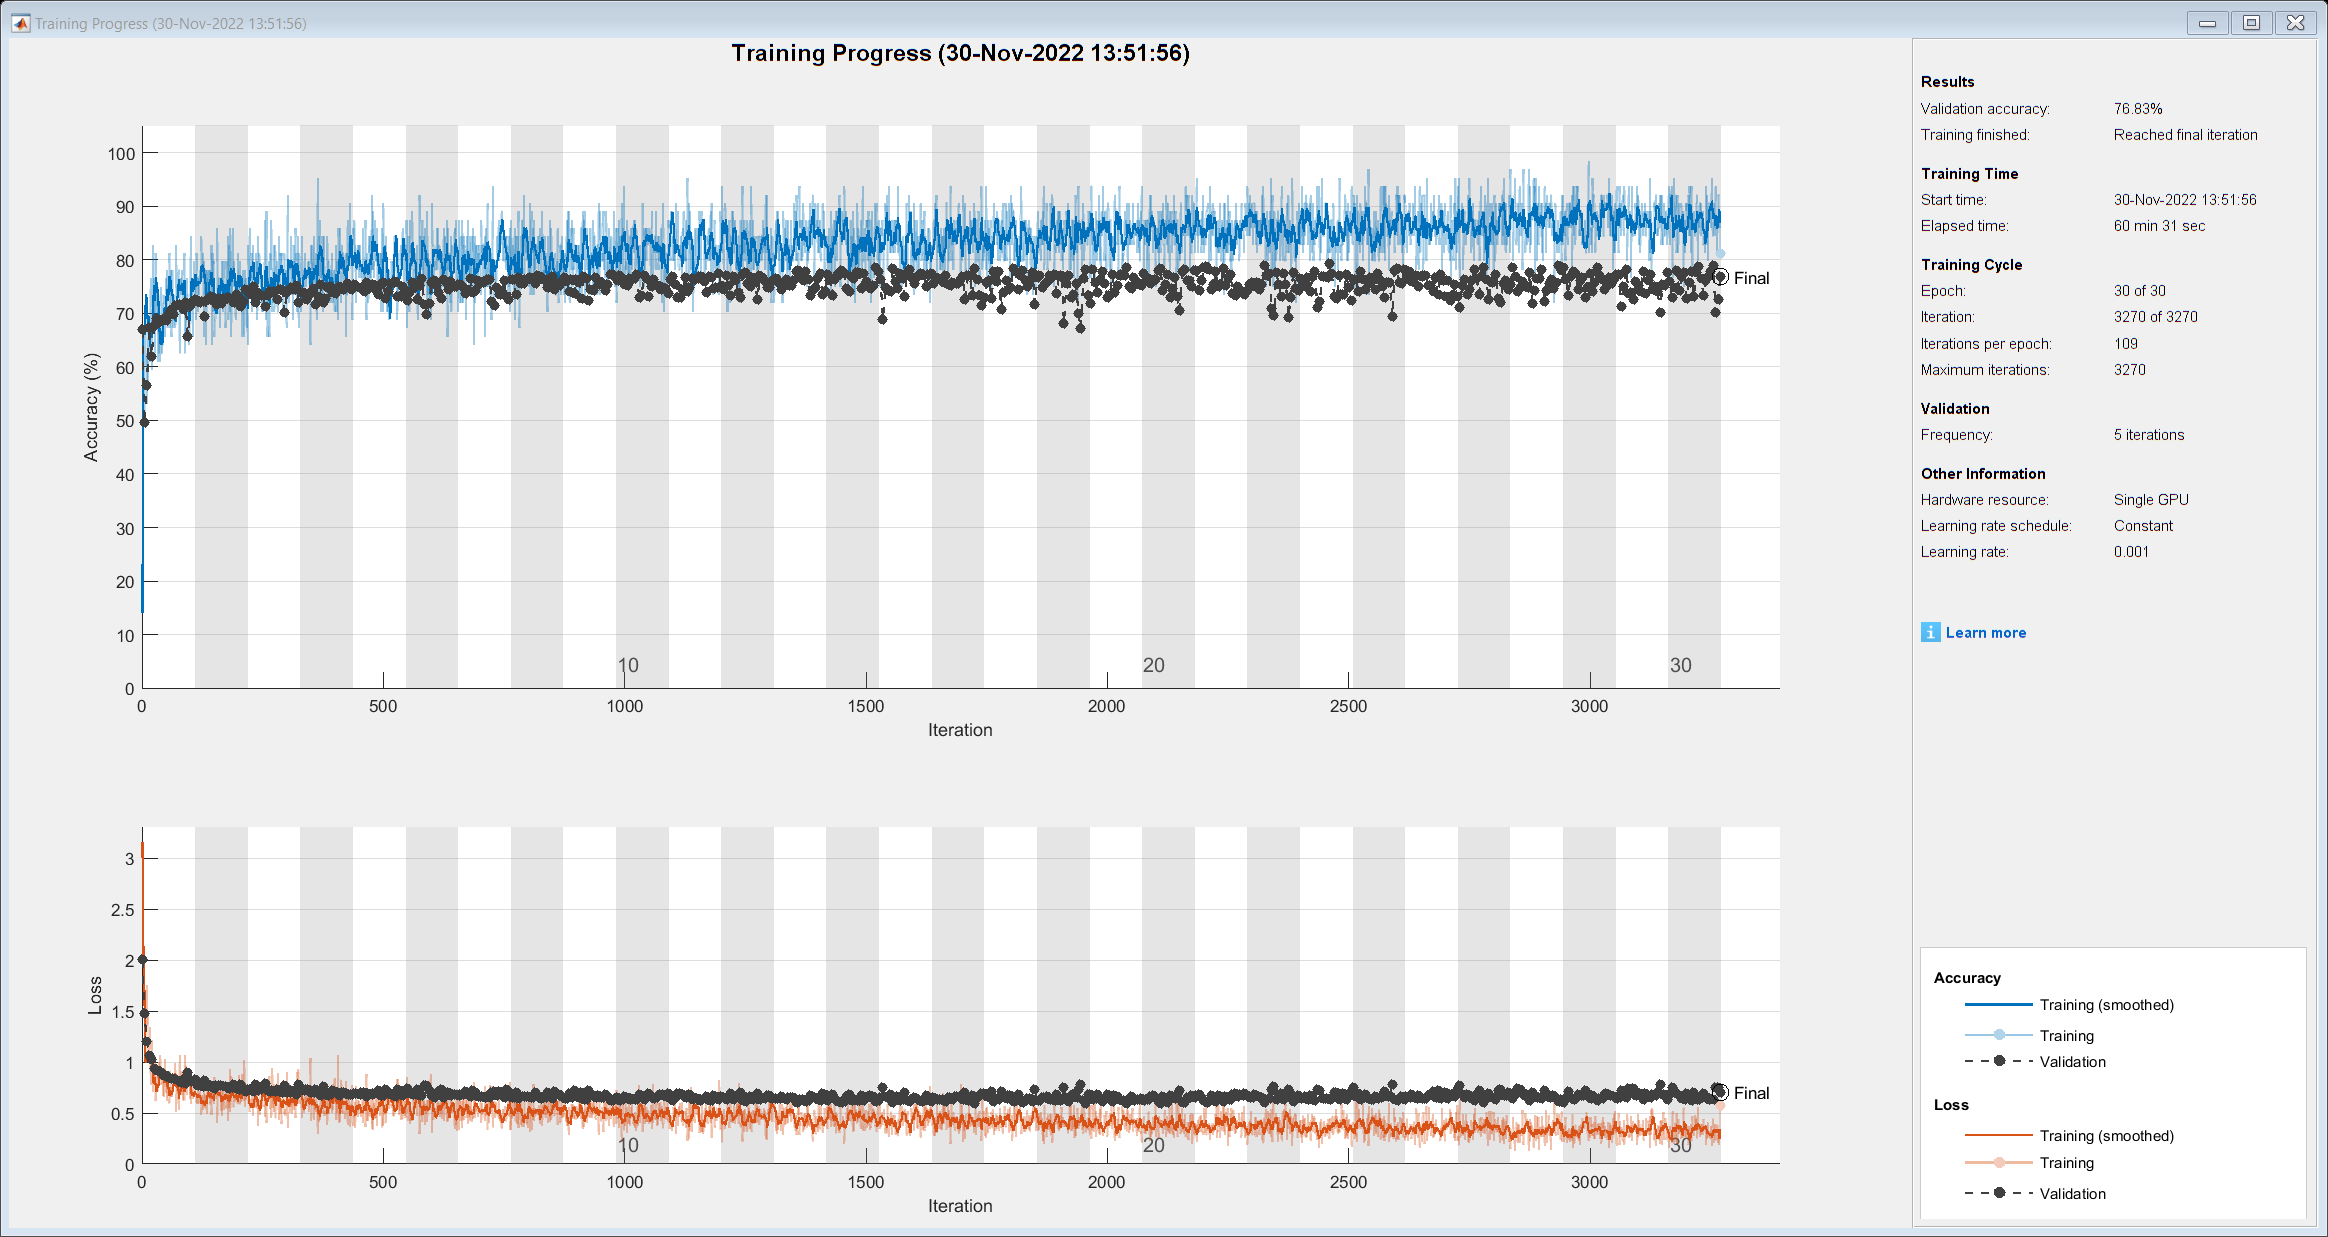

[net, traininfo] = trainNetwork(augimdsTrain,lgraph,opts);

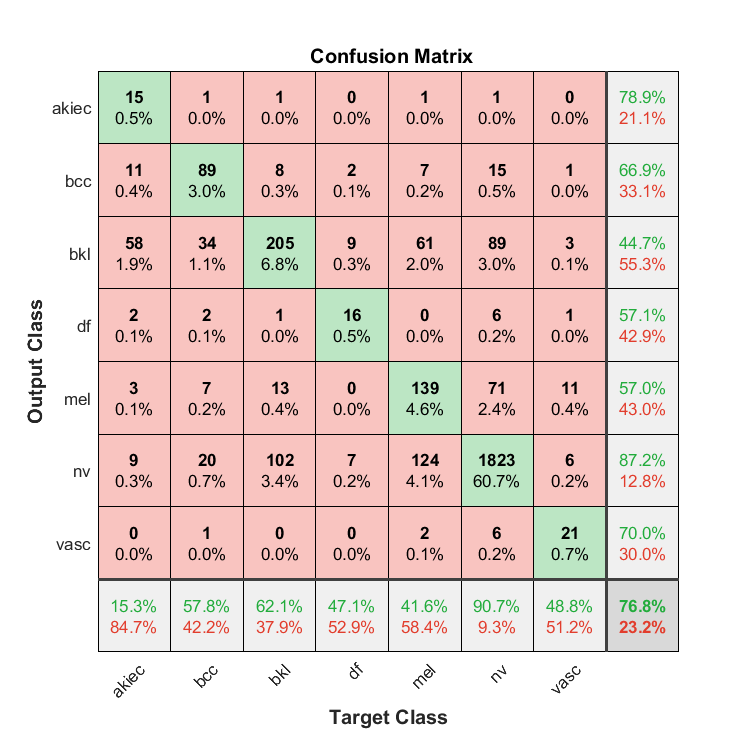

yPred = classify(net, imdsValidation);
yTest = imdsValidation.Labels;
plotconfusion(yTest, yPred)

figure
cm = confusionchart(yTest, yPred)

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [7×7 double]
         ClassLabels: [7×1 categorical]

  Show all properties


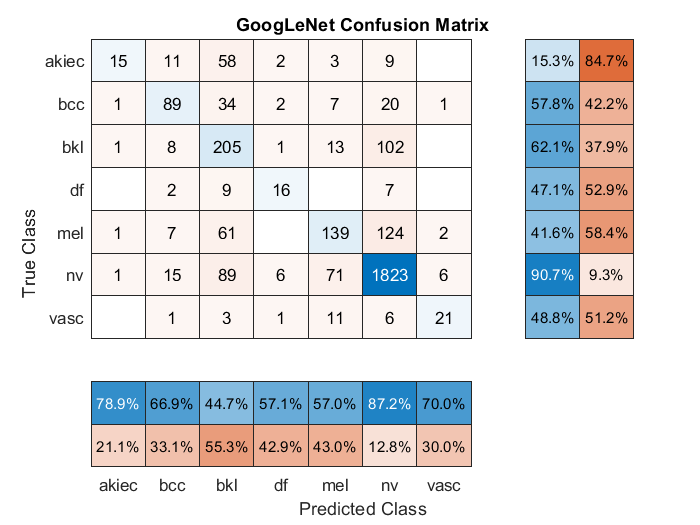

cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'GoogLeNet Confusion Matrix';